# Template Gallery

We've created a gallery containing a number of interesting and useful quantum graphs. 

Each template consists of two MATLAB functions stored as mfiles.

- `<TEMPLATE>.m` This file can be called on its own, or using the wrapper function `quantumGraphFromTemplate`. Each template file has default settings, set in an `arguments` block, or else the parameters can be set as optional arguments, using name-value pairs.

- `<TEMPLATE>PlotCoords.m` Sets the plot coordinates. The file  `quantumGraphFromTemplate` calls both parts of the template together.

### Star

The default layout has three equal-length edges

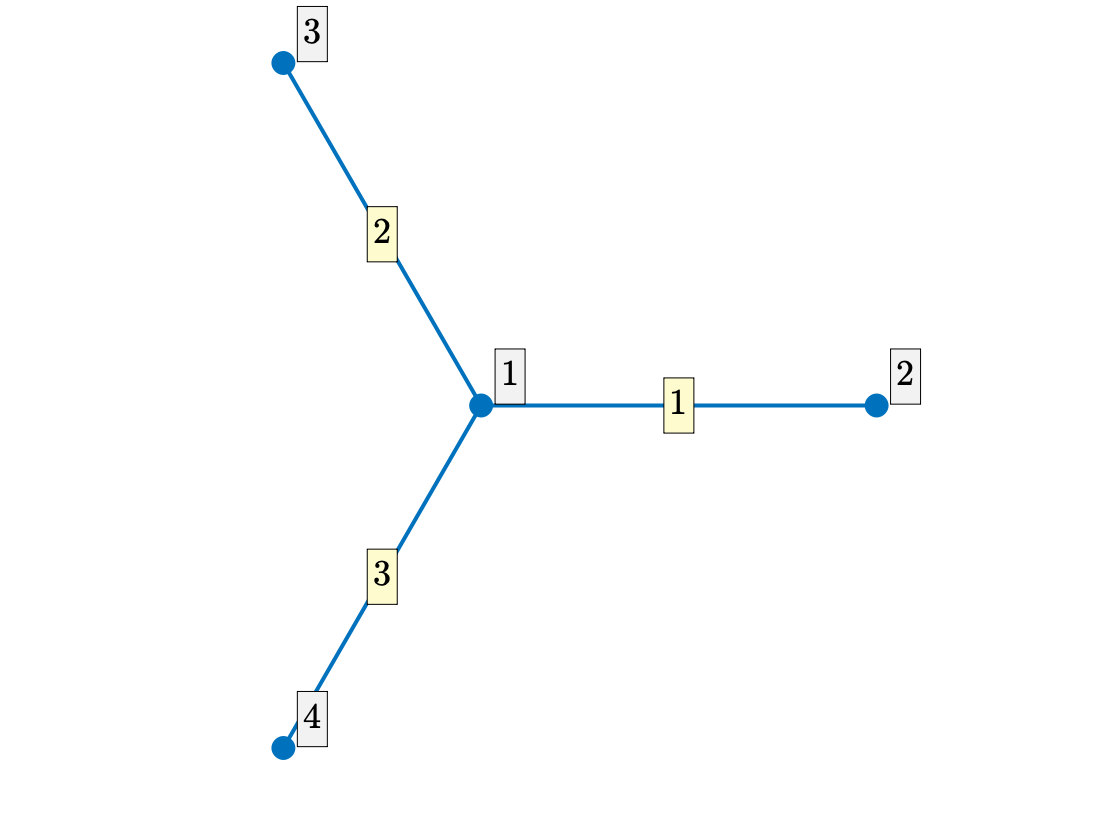

Phi=quantumGraphFromTemplate('star');
Phi.plot('layout')

A 6-pointed star with edge lengths chosen at random between 5 and 10 and Dirichlet conditions on the end of the final two edges. Plot the ground state of the Laplacian

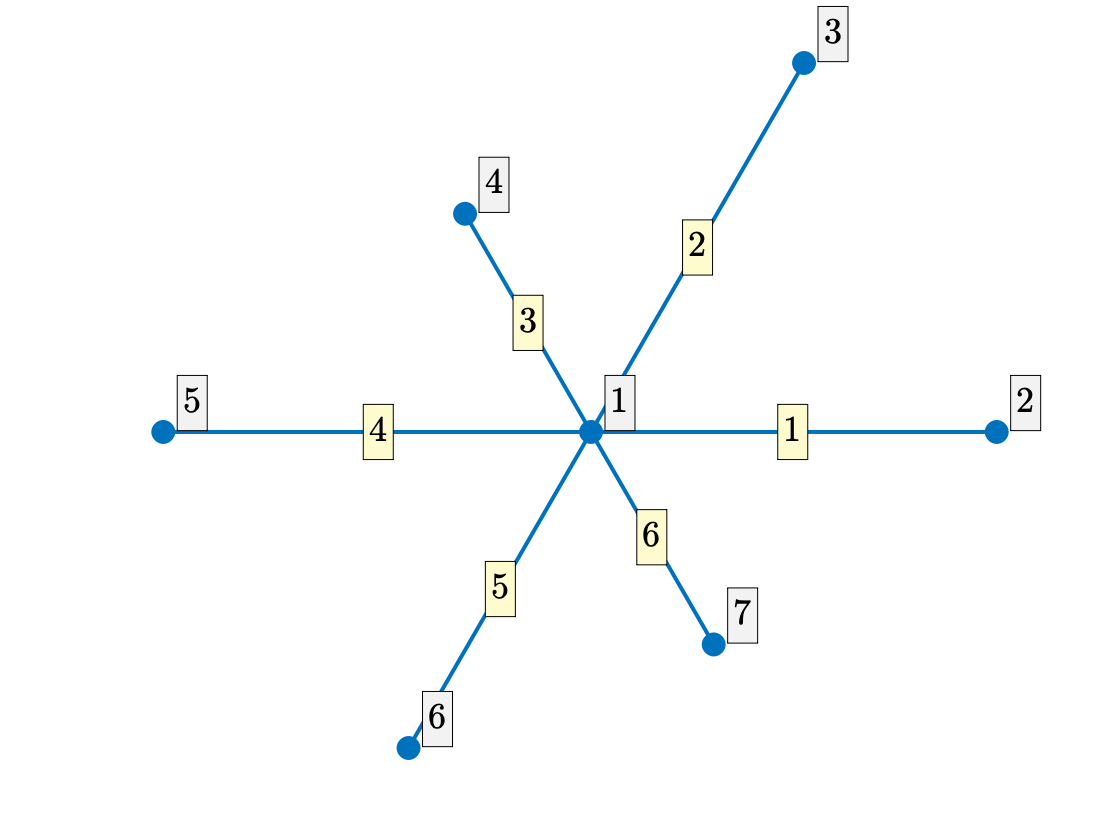

n=6;
L=5*(1+rand(n,1));
robinCoeff=zeros(n+1,1); robinCoeff(n:n+1)=nan;
Phi=quantumGraphFromTemplate('star','n',6,'LVec',L,'robinCoeff',robinCoeff);
Phi.plot('layout')

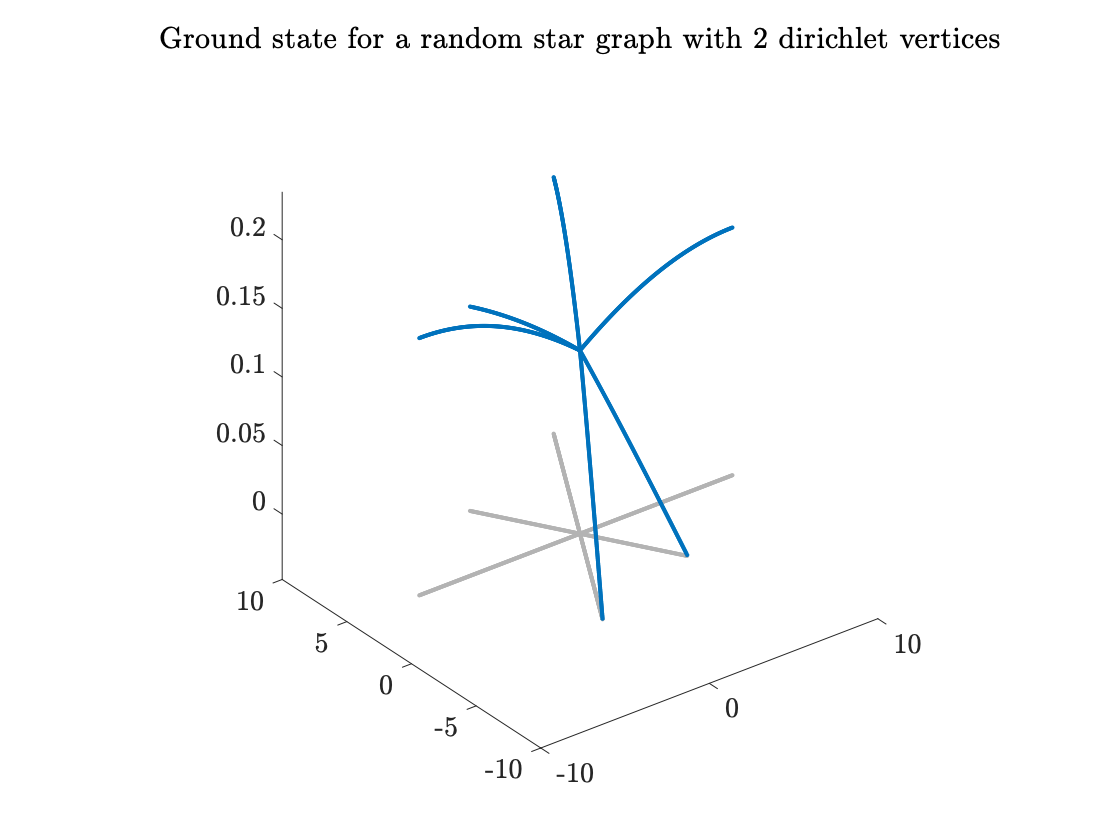

figure;
[V,lambda]=eigs(Phi,1);
Phi.plot(V(:,1))
title('Ground state for a random star graph with 2 dirichlet vertices')

### Dumbbell

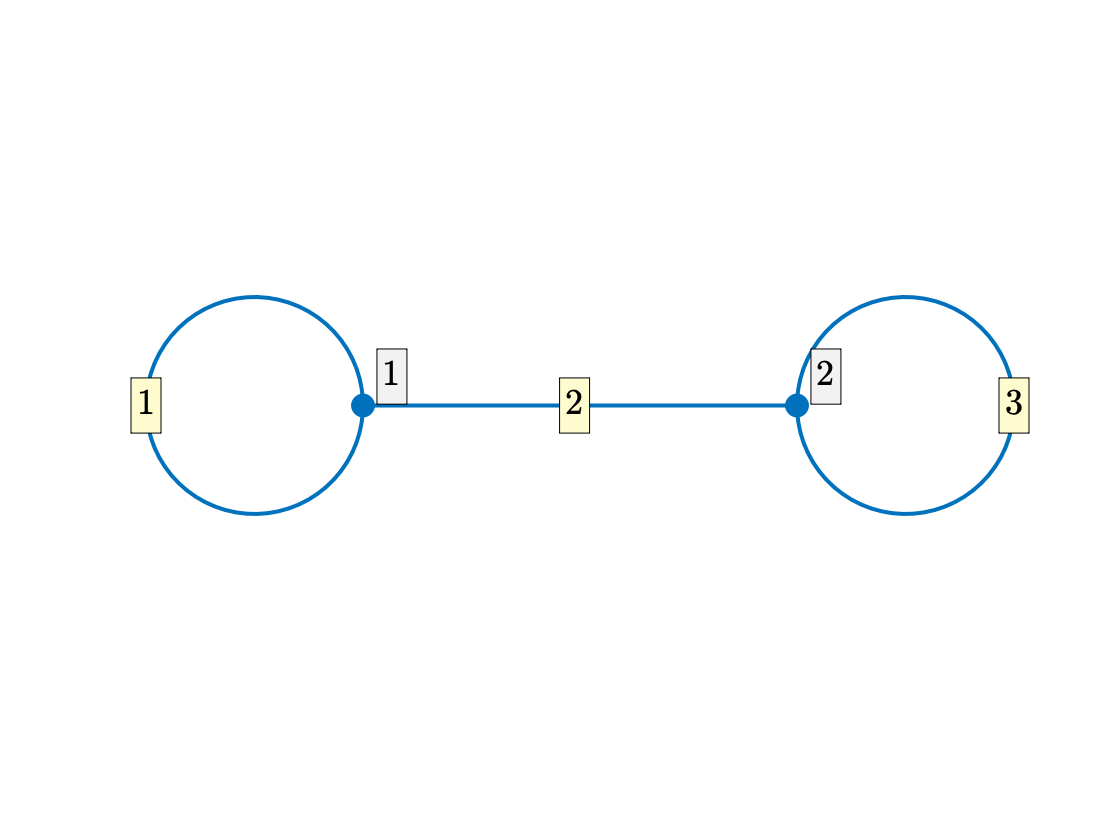

Phi=quantumGraphFromTemplate('dumbbell');
Phi.plot('layout')

Here we apply evaluate a gaussian of random amplitude on each edge and plot the results

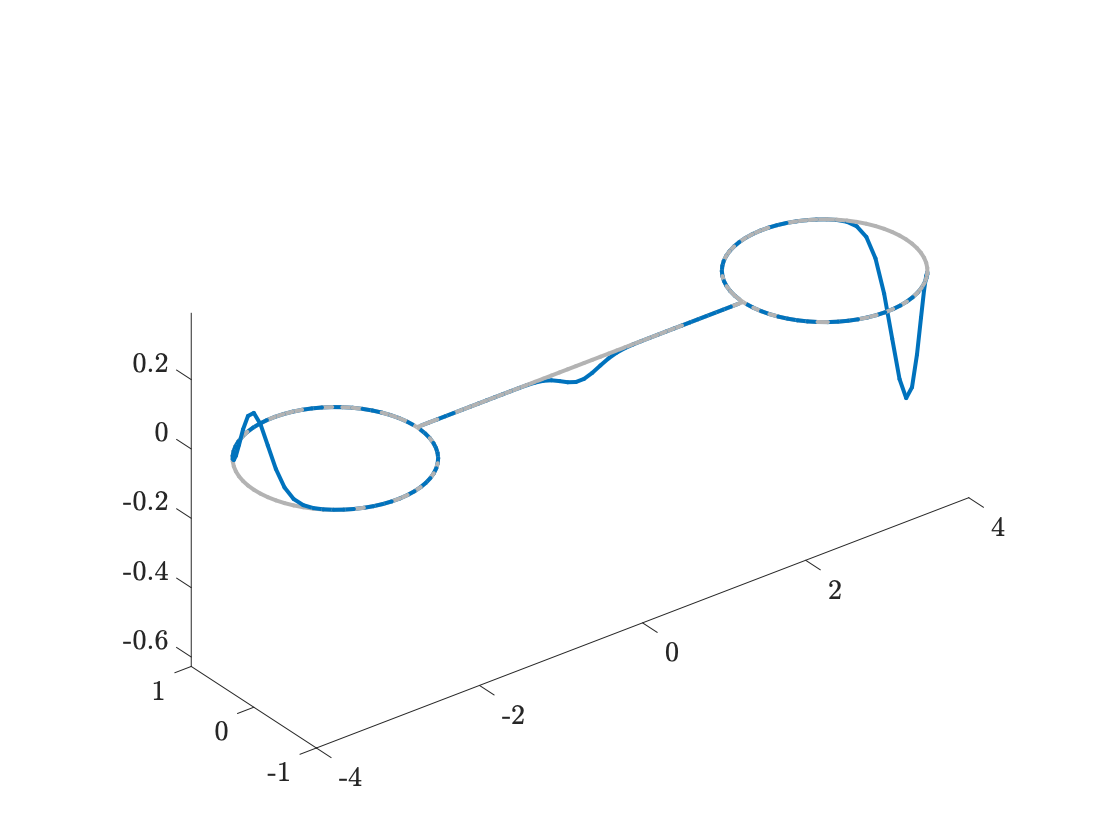

for k=1:3
    f=@(x) (0.5-rand(1))*exp(-(10*(x-Phi.L(k)/2).^2));
    Phi.applyFunctionToEdge(f,k)
end
Phi.plot;

### multibell

Generalization of the dumbbell consisting of $n$ lollipops/tadpoles joined by their stems. By default $n=3$ and all the lollipops are identical, but they need not be.

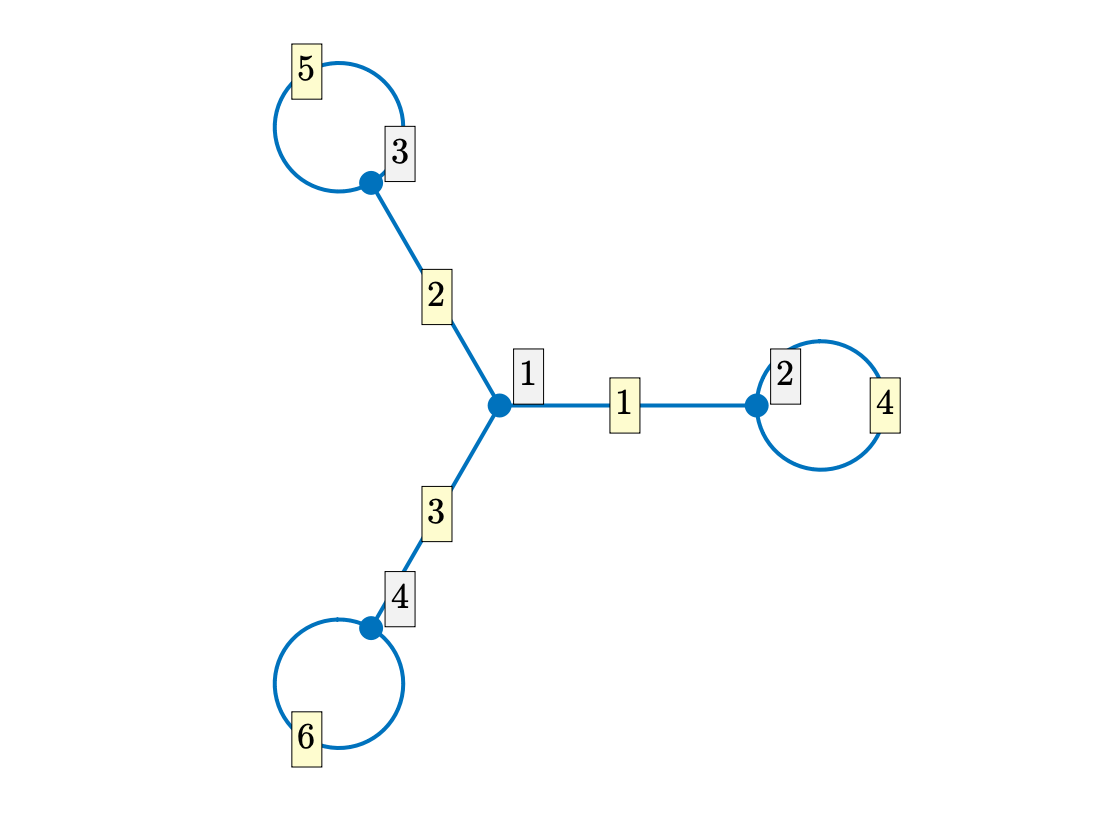

Phi=quantumGraphFromTemplate('multibell');
Phi.plot('layout')

If $n=1$we recover the lollipop/tadpole

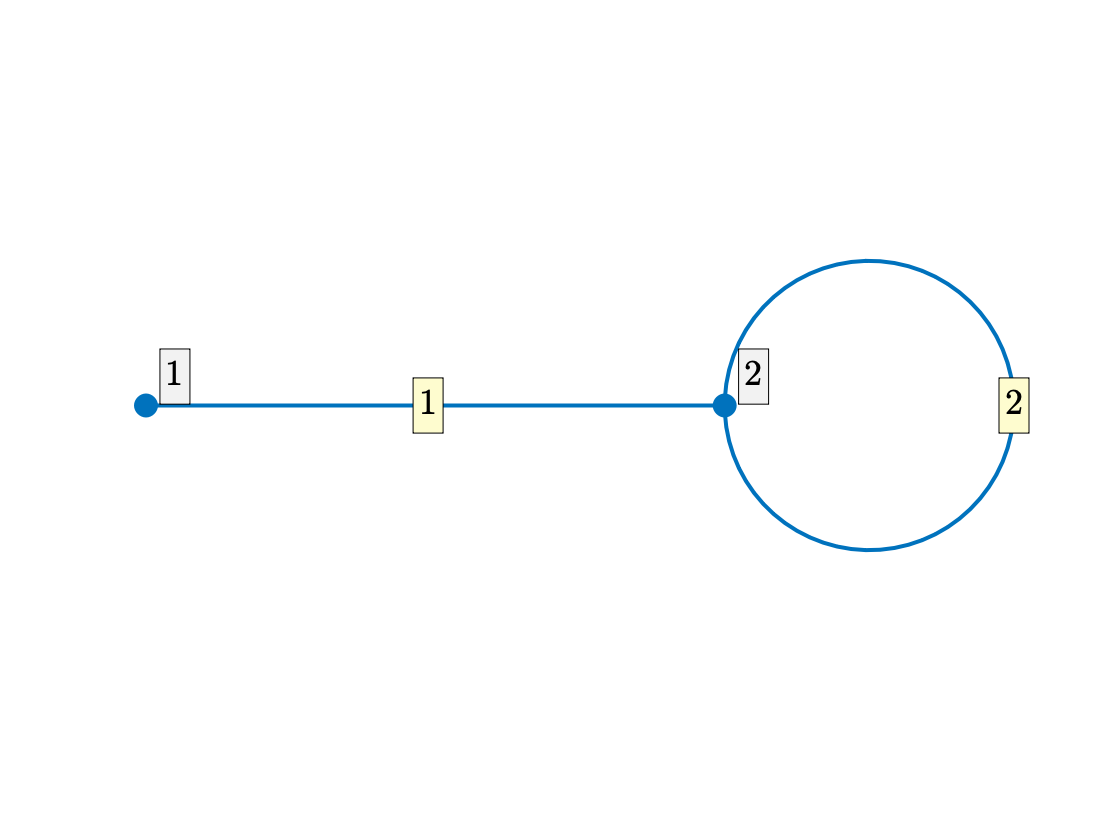

Phi=quantumGraphFromTemplate('multibell','nBells',1);
Phi.plot('layout')

### Wheel

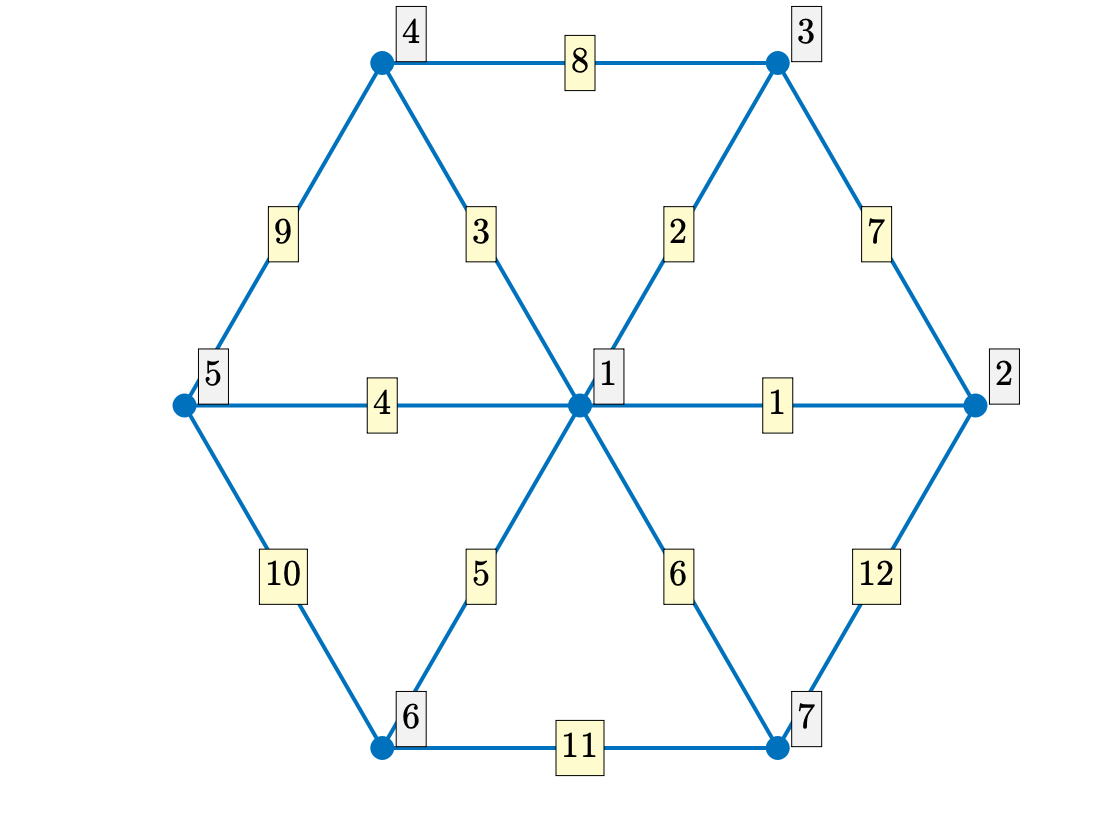

Phi=quantumGraphFromTemplate('wheel');
Phi.plot('layout')

### Helm

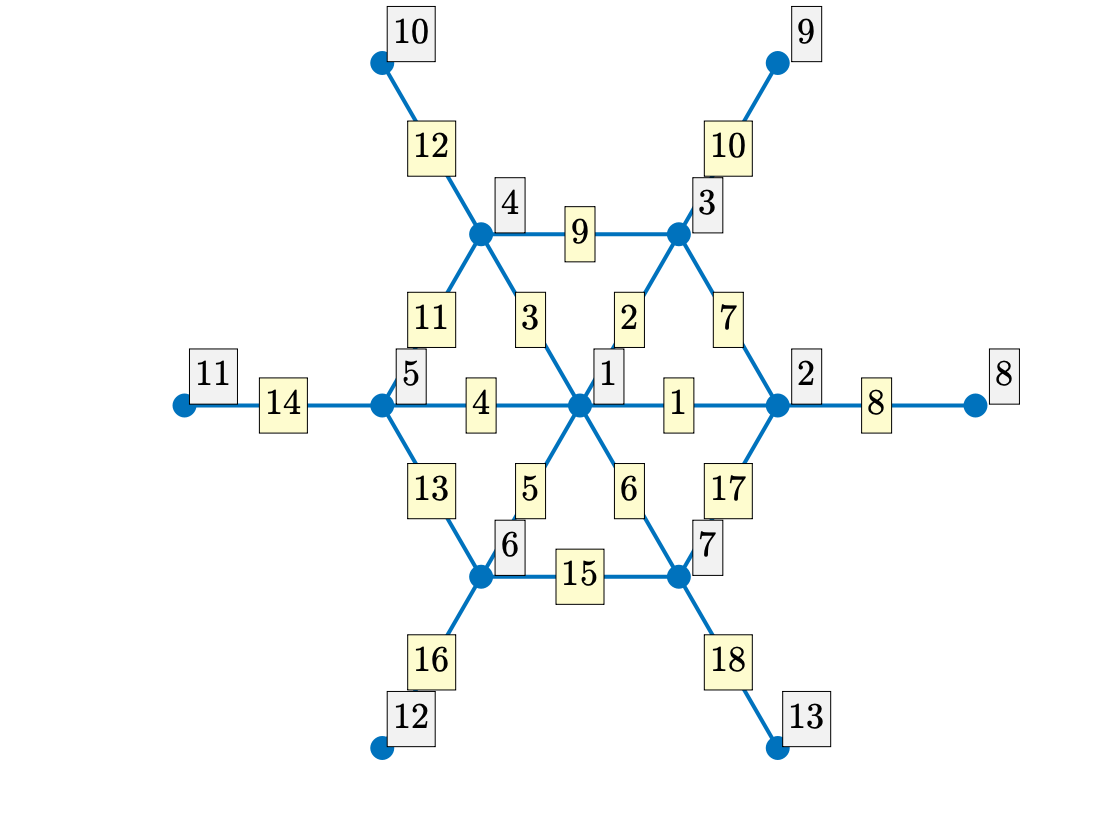

Phi=quantumGraphFromTemplate('helm');
Phi.plot('layout')

### Spiderweb

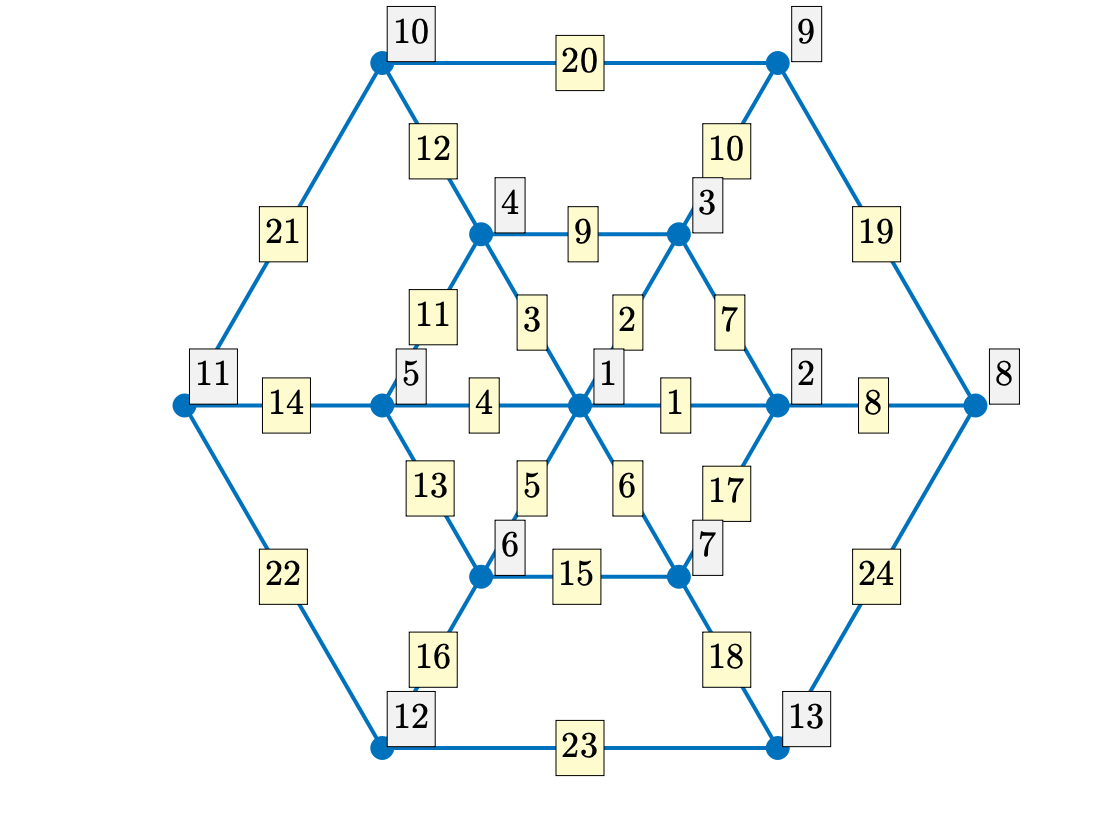

Phi=quantumGraphFromTemplate('spiderWeb');
Phi.plot('layout')

### Sunlet

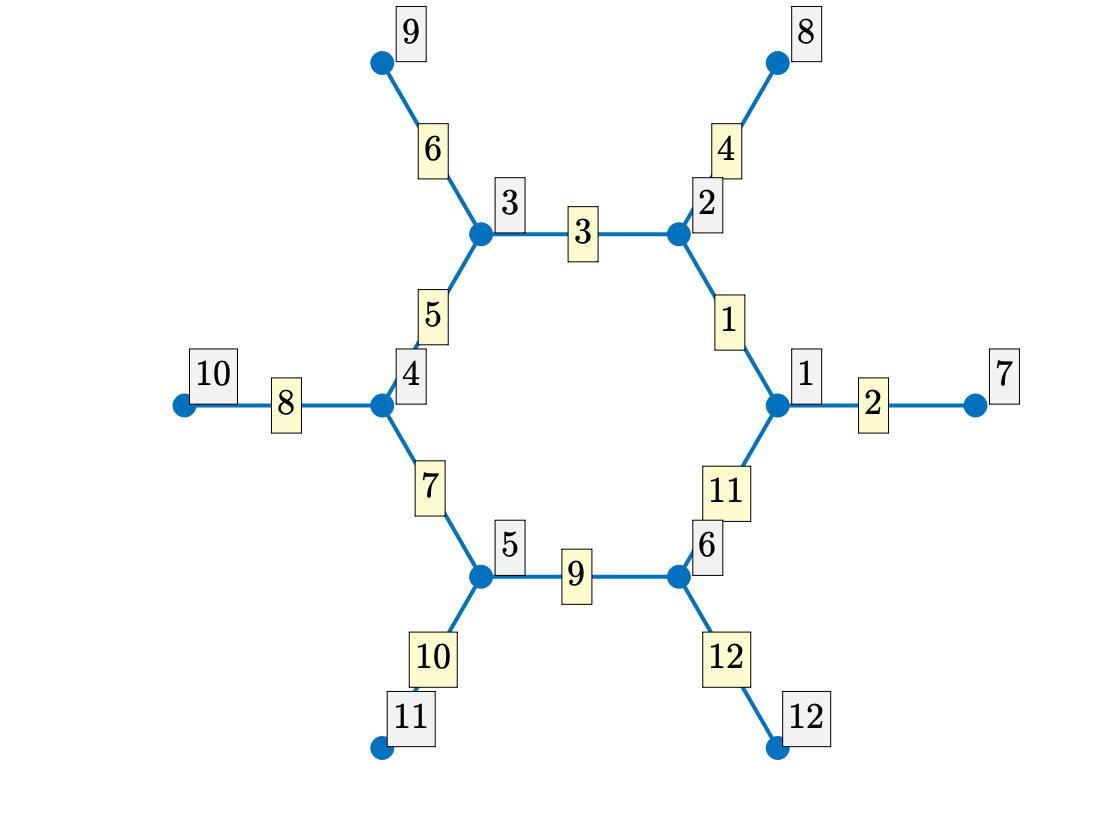

Phi=quantumGraphFromTemplate('sunlet');
Phi.plot('layout')

### Bubble Tower

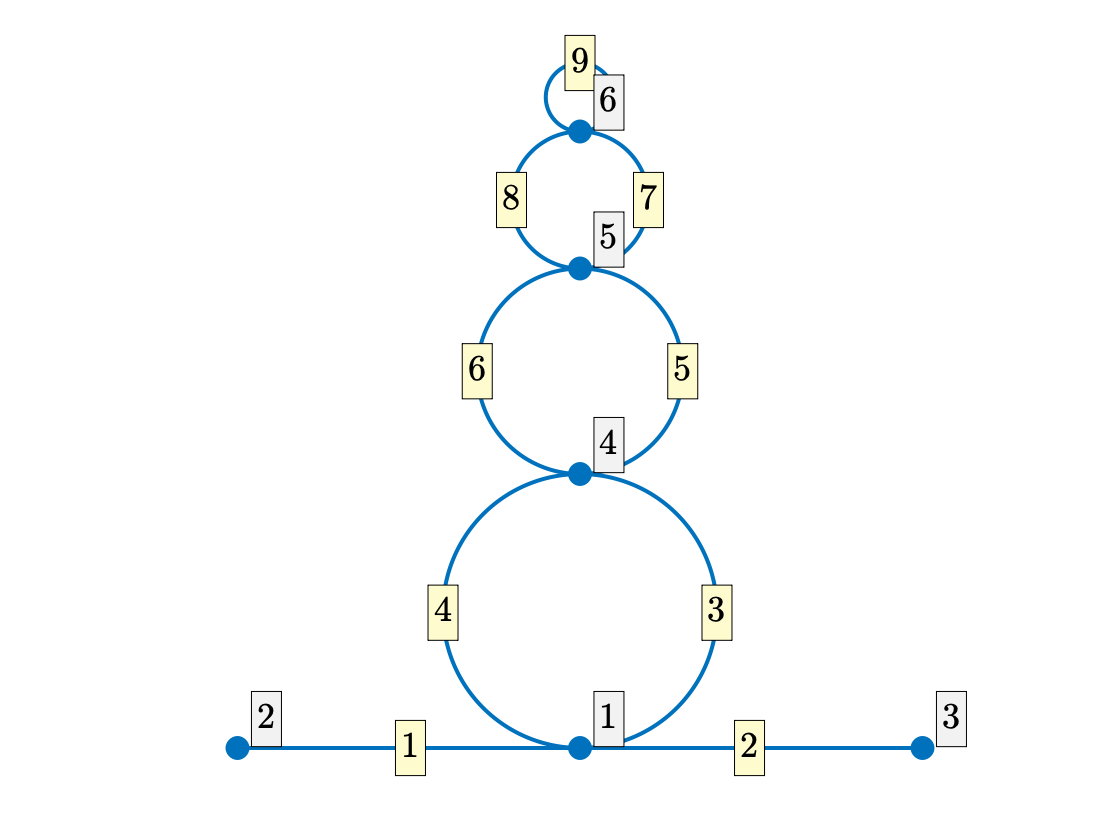

Phi=quantumGraphFromTemplate('bubbleTower','circumferences',[4 3 2 1]*2*pi);
Phi.plot('layout')

### Berkolaiko-Marzuola Pelinovsky

This is the example from 

G. Berkolaiko, J. L. Marzuola, and D. E. Pelinovsky. Edge-localized states on quantum graphs in the limit of large mass. *Ann. Inst. Henri Poincare* C, 38:1295–1335, 2020.

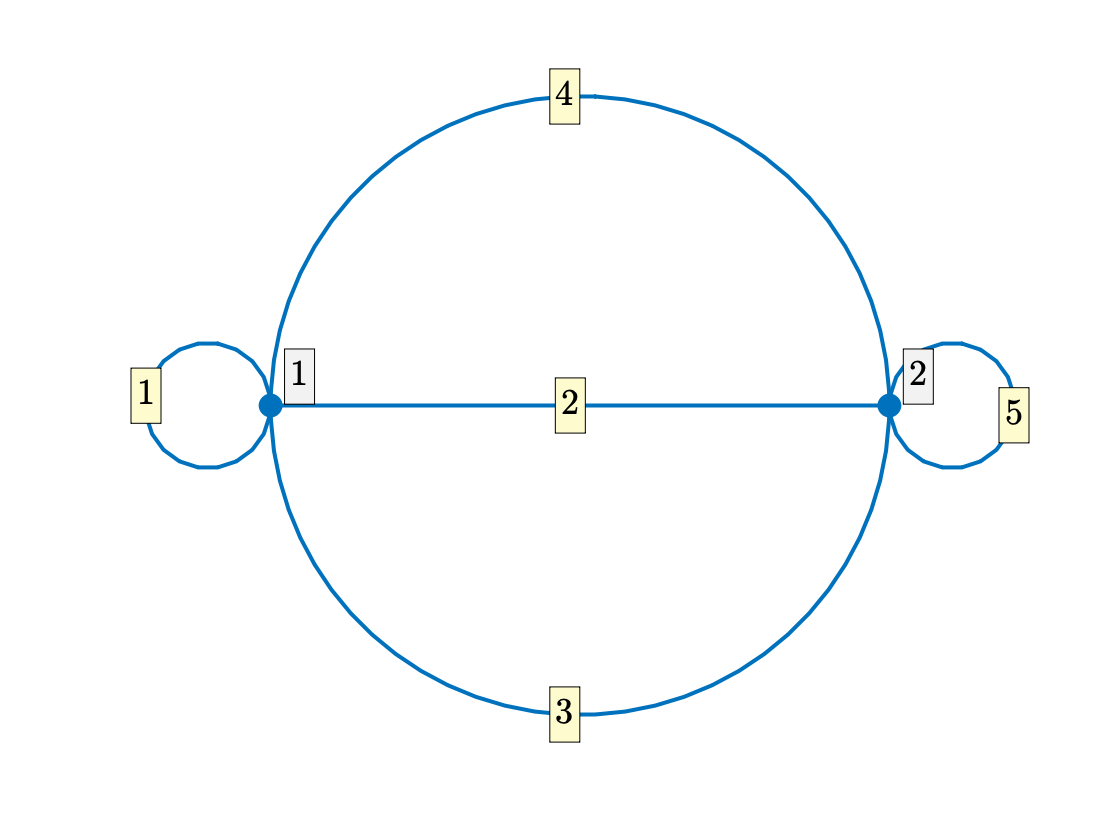

Phi=quantumGraphFromTemplate('BMP');
Phi.plot('layout')

#### Necklace graph

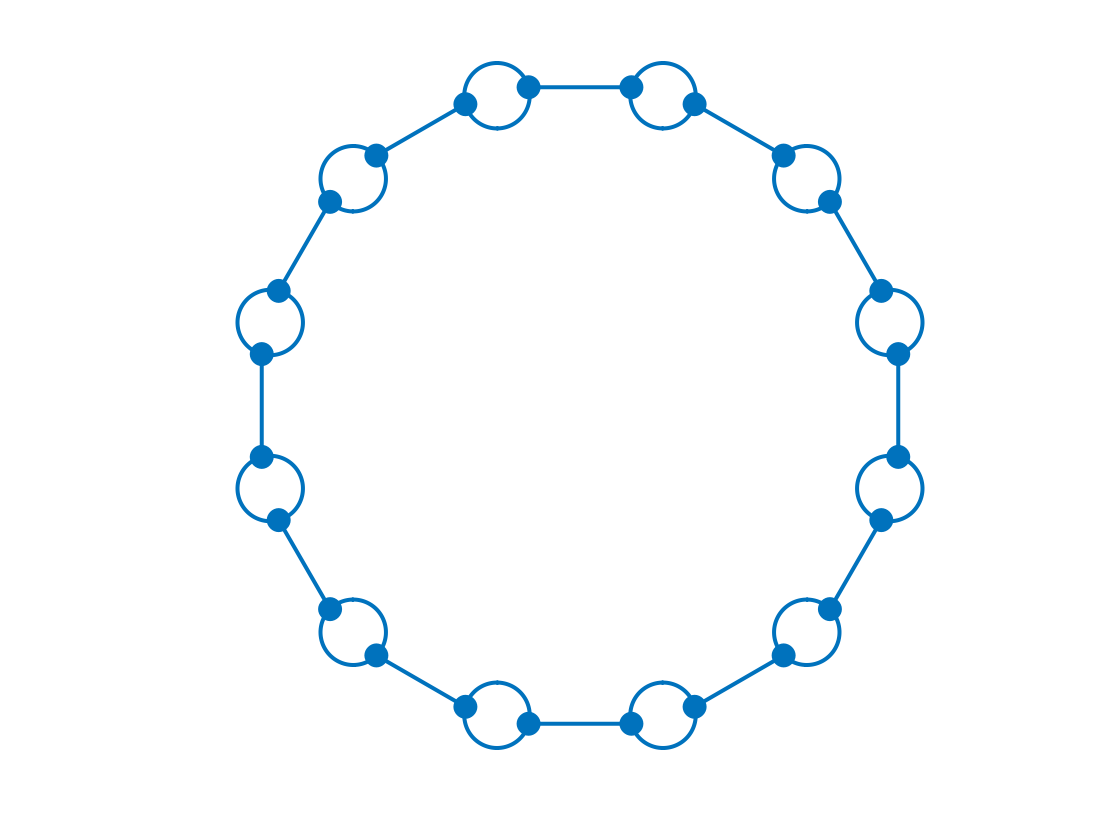

Phi=quantumGraphFromTemplate('necklace','LString',0.5,'LPearl',pi,'nPearls',12);
Phi.plot('mutelayout')

## Two dimensional lattice templates

The following templates assume that the nodes are at lattice points. They do not need a separate `plotCoordinates` function. Instead they use the program `plotCoordFcnFromNodes`. 

### Rectangular Array

Windowscreen graph. In this graph, it is easier to simultaneously specify the layout geometry and create the graph. Therefore we call the template directly instead of using the `quantumGraphFromTemplate` wrapper. 

We also introduce the `'mutelayout'` option to plot the layout of the graph without labeling the edges and vertices.

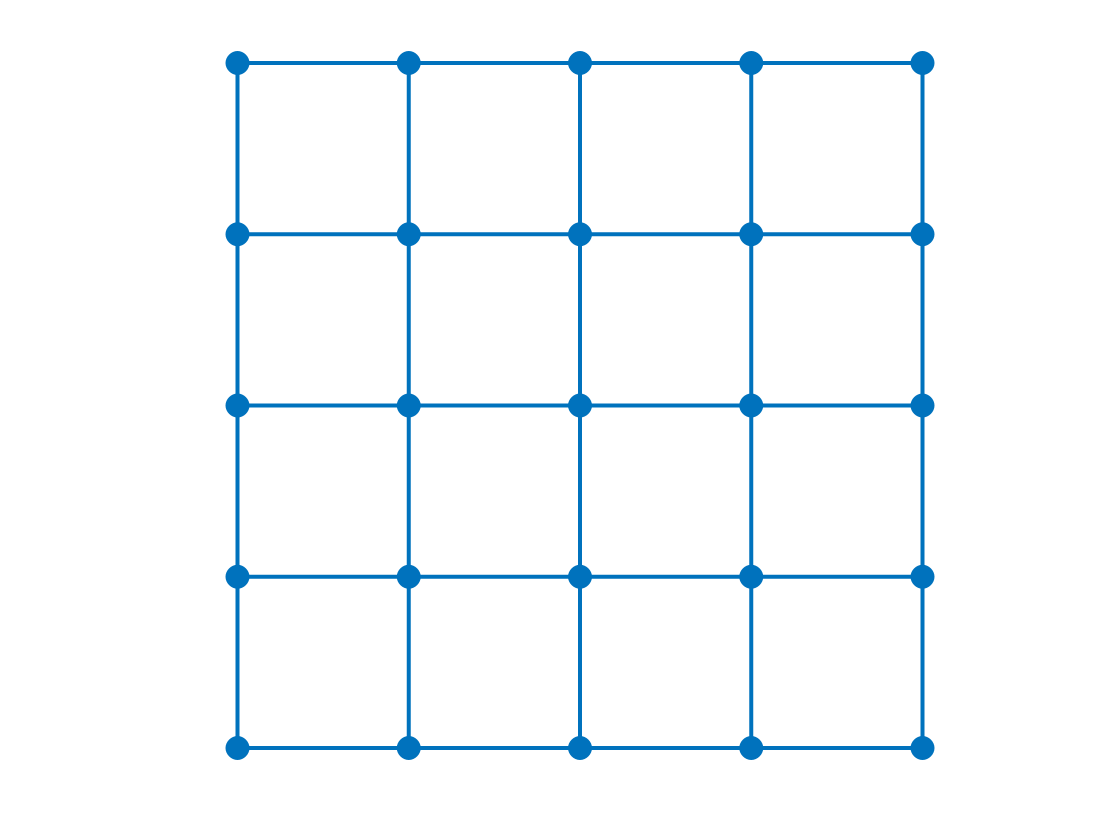

Phi=rectangularArray('nx1',4,'nx2',4);
Phi.plot('mutelayout')

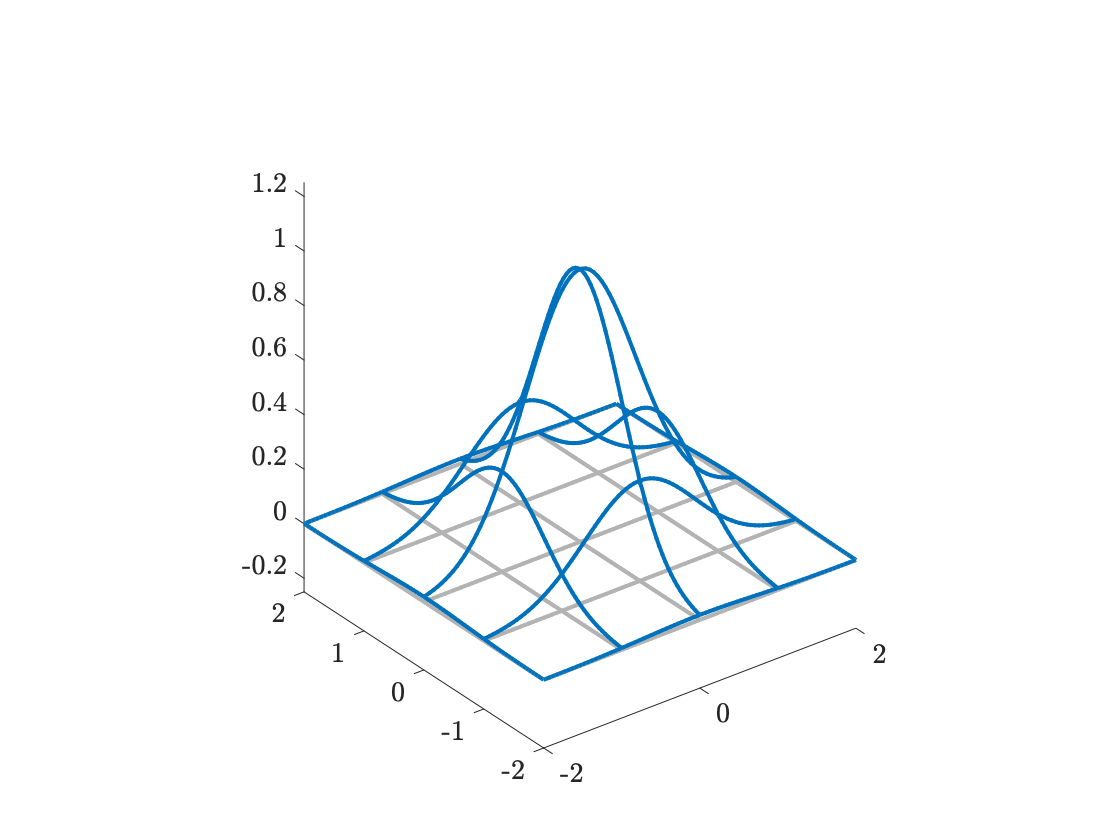

f=@(x1,x2) exp(-x1.^2-x2.^2);
Phi.applyGraphicalFunction(f);
Phi.plot

### Triangular Array

In this graph, it is easier to simultaneously specify the layout geometry and create the graph. Therefore we call the template directly instead of using the `quantumGraphFromTemplate` wrapper. 

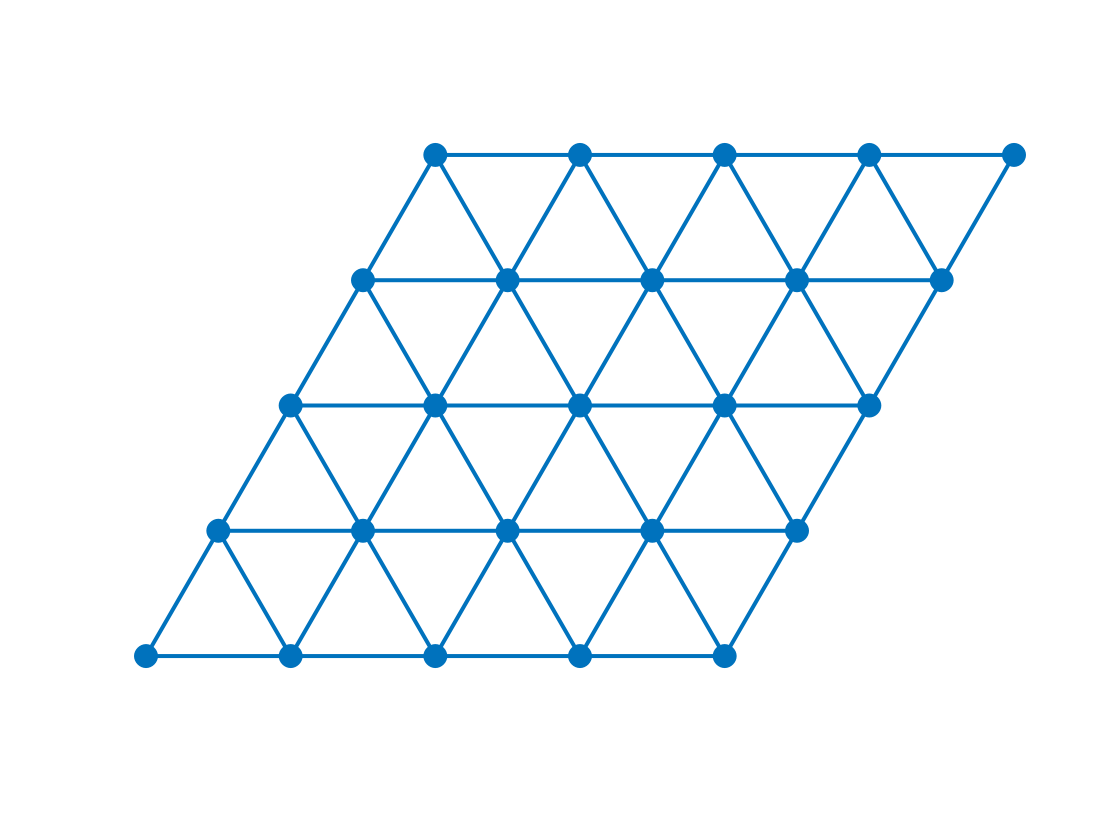

Phi=triangularArray('nx1',4,'nx2',4);
Phi.plot('mutelayout');drawnow

We can also specify the periods. The template constructor will throw an error if an edge length is zero or the two edges are close to parallel/antiparallel

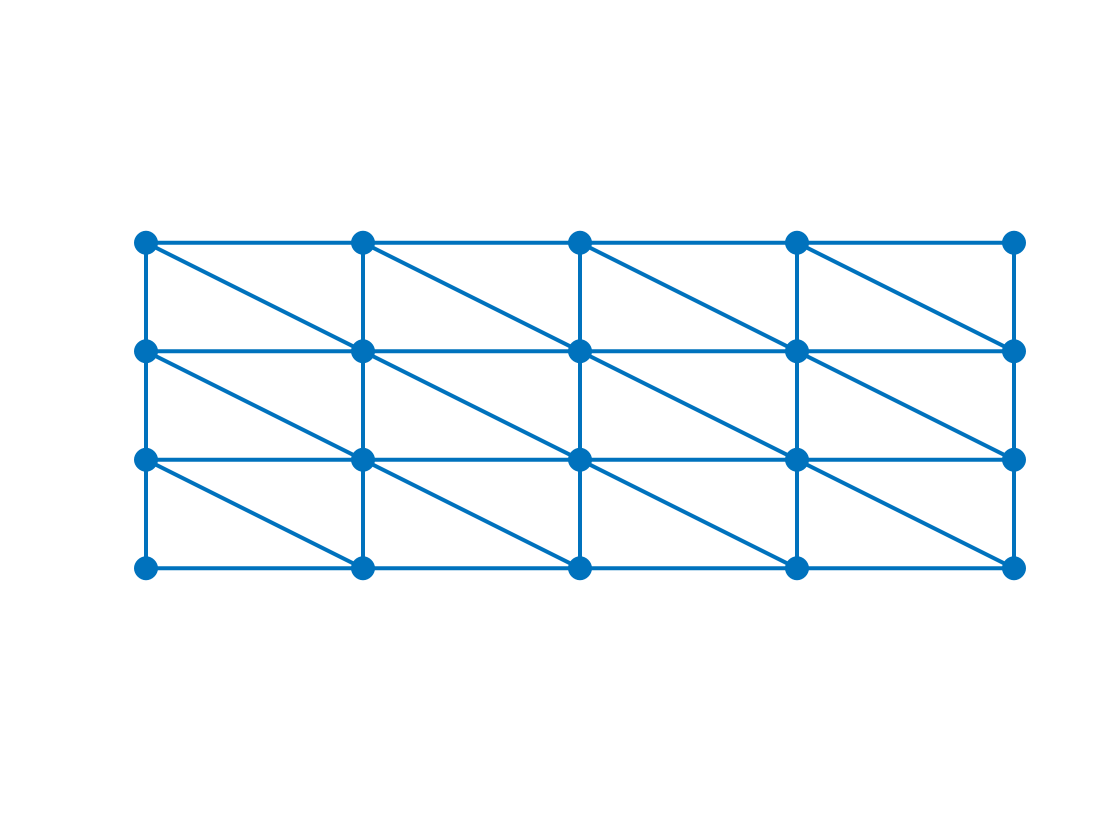

Phi=triangularArray('nx1',4,'nx2',3,'v1',[2 0],'v2',[0 1]);
Phi.plot('mutelayout')

### Hexagonal Array

In this graph, it is easier to simultaneously specify the layout geometry and create the graph. Therefore we call the template directly instead of using the `quantumGraphFromTemplate` wrapper. 

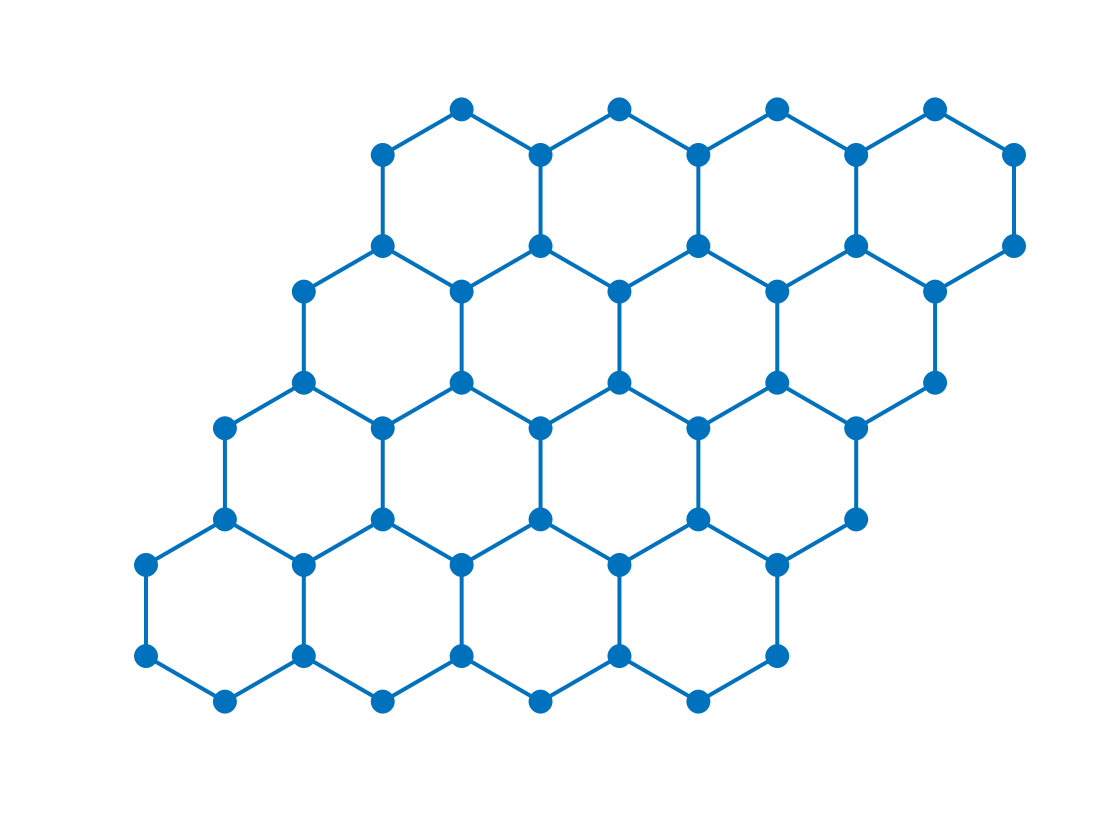

Phi=hexagonalArray('nx1',4,'nx2',4);
Phi.plot('mutelayout');

### Hex of hexes  

Here we compute the first two non-constant eigenfunctions and render them with the quantum graph version of `pcolor`. Unlike the example given for the dumbbell, here we do not post-process the eigenfunctions in order to ensure that the multiplicity-two eigenfunctions are (1) symmetric with respect to the graph geometry or that they are orthogonal. We can see from the nodal points, labeled with black dots, that the nodes are not aligned along the symmetry axes of the graph. We also find that the dot product of these two functions is non-zero, indicating that MATLAB has not run them through Gram-Schmidt. Indeed,  MATLAB does not "know" there is a double eigenvalue, since the computed eigenvalues differ slightly.

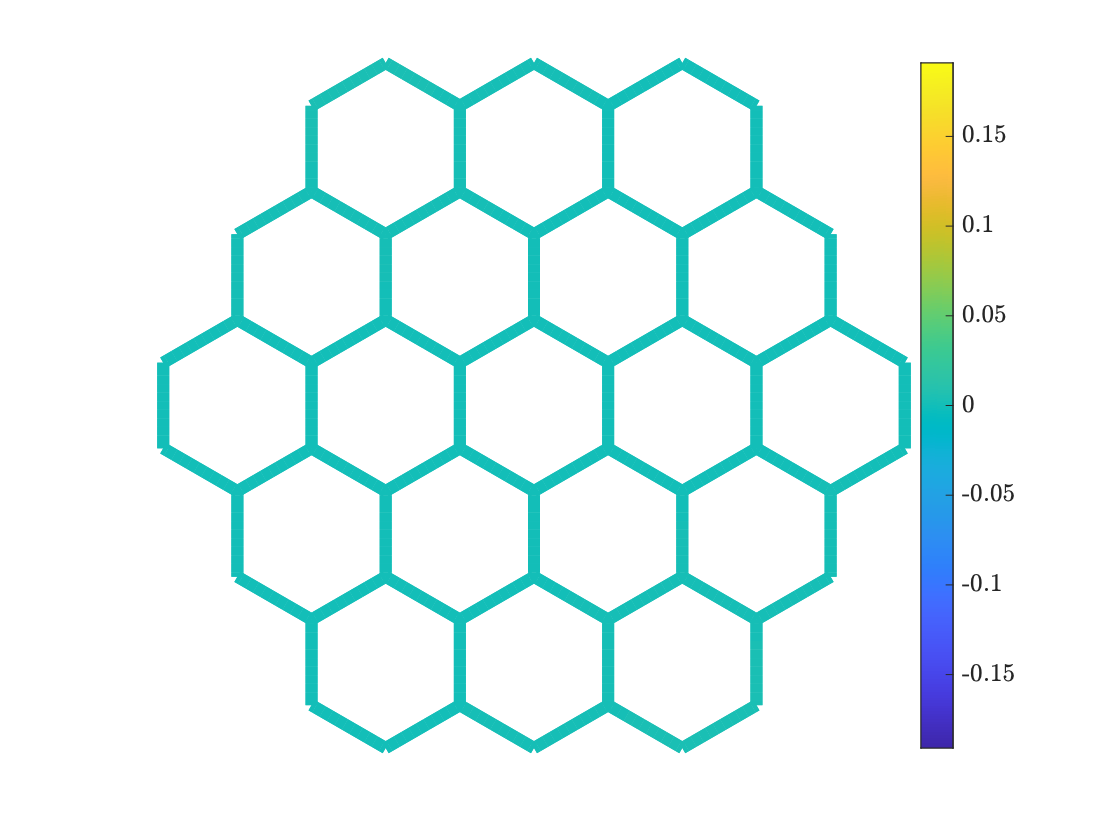

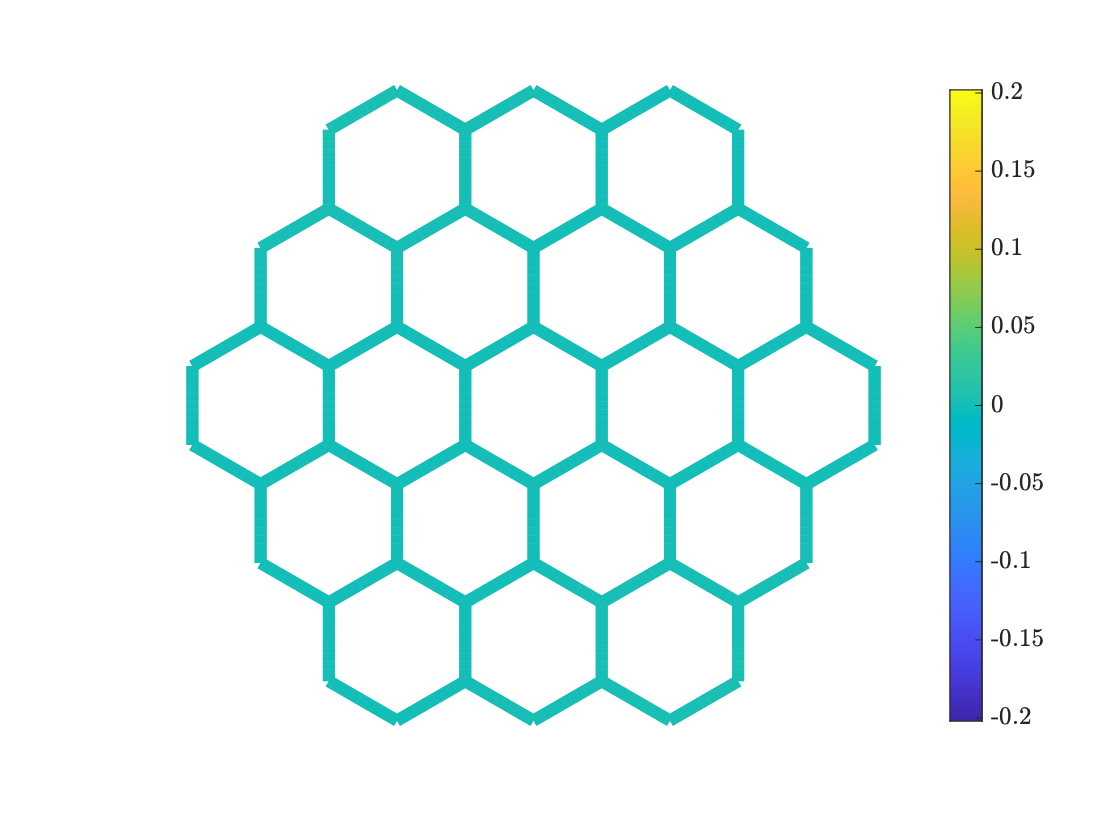

Phi=hexOfHexes("cellsPerSide",3);
[V,~]=Phi.eigs(3);
Phi.pcolor(V(:,2)); figure; Phi.pcolor(V(:,3))

### Periodic Hexagonal Grid

This is a demonstration (the only one so-far written) of a perioidic template. It creates two quantum graphs: `Phi`, which is used for computation, and which is genuinely periodic. Certain edges have been tagged because they cross the edge of a period cell and are plotted in red when the graph is laid out, and `PhiX`, the extended graph which is only used for plotting, as well as a function `extensionMap` which is used to copy values from the edges and vertices on the smaller graph to those on the larger graph

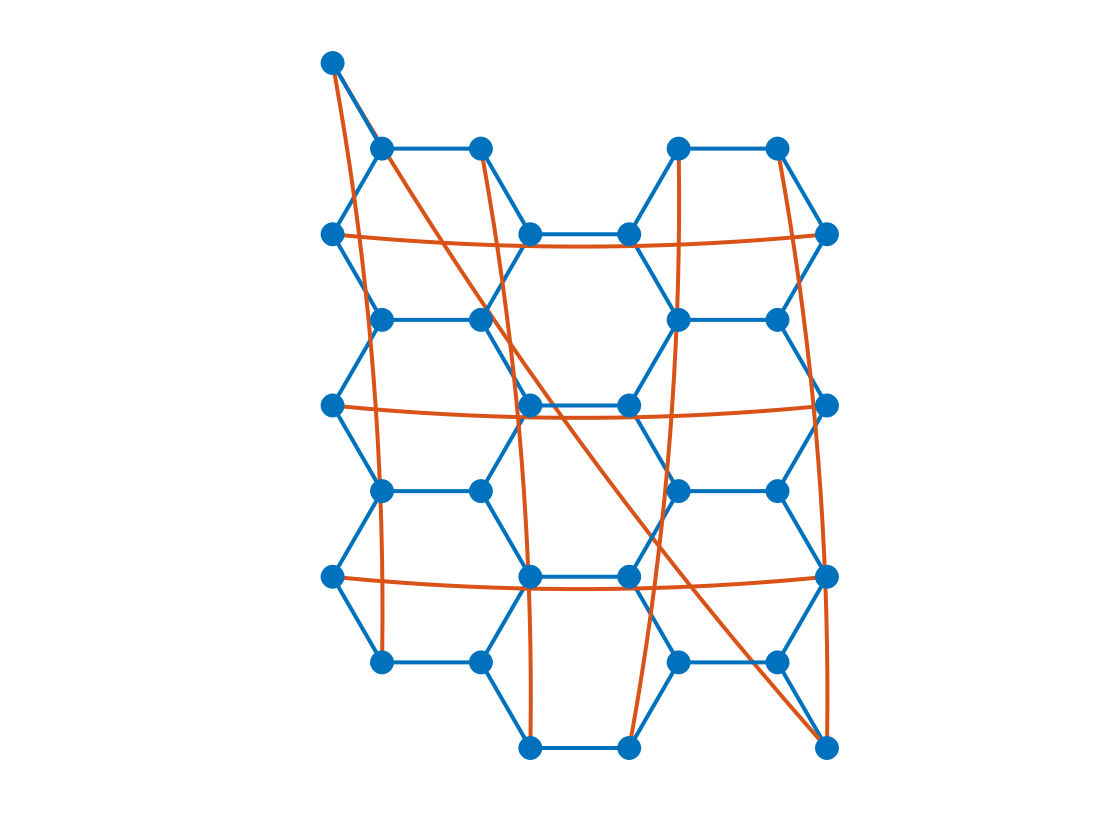

[Phi,PhiX,extensionMap] =hexGridPeriodic(nx1=4,nx2=4,nx=20);
Phi.plot('mutelayout')

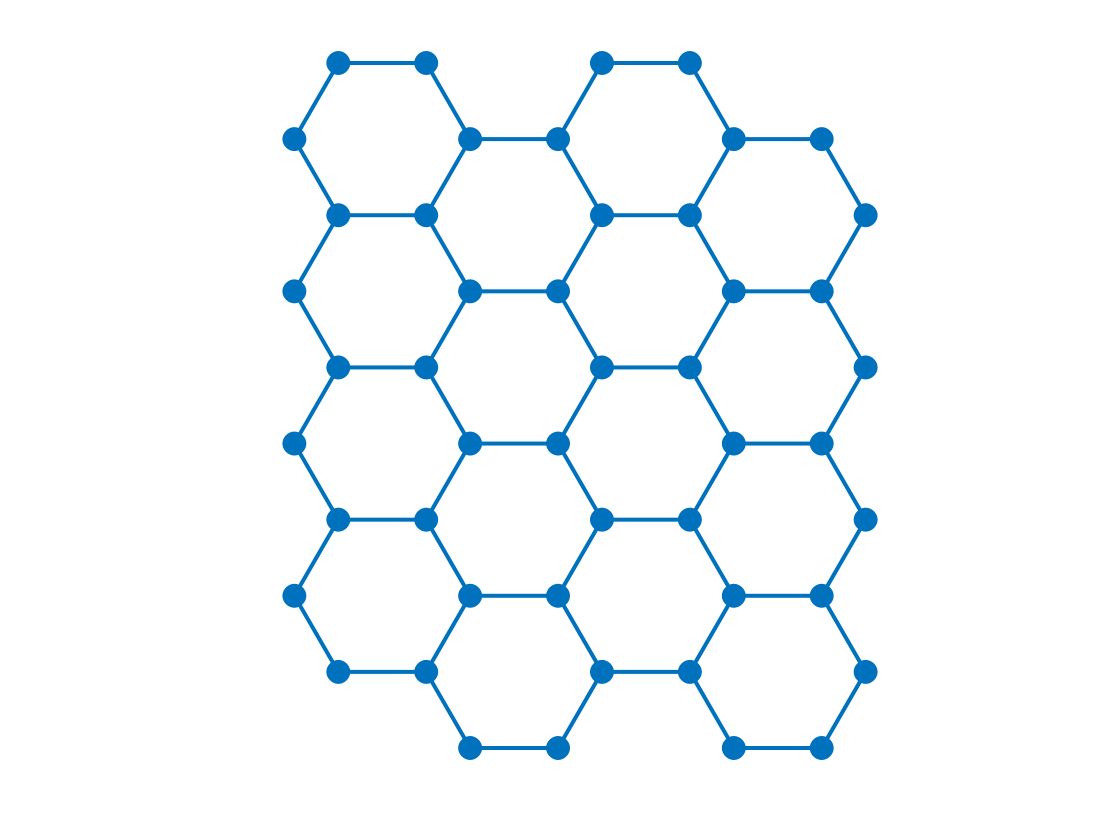

figure;
PhiX.plot('mutelayout')

Next we compute some eigebvalues and eigenvectors. Computed eigenvalues 6-9 represent a single eigenvalue with algebraic and geometric multiplicity four.  We first orthogonalize this eigenspace, before plotting the orthonormal eigenfunctions.

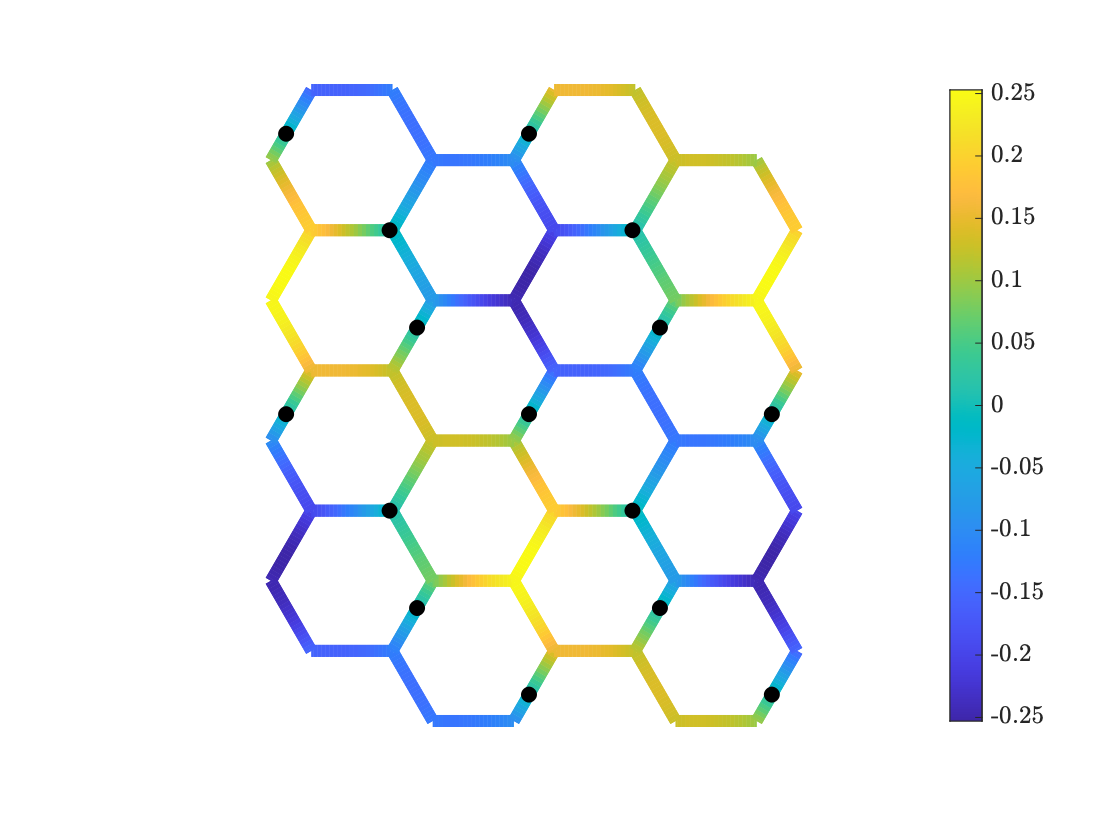

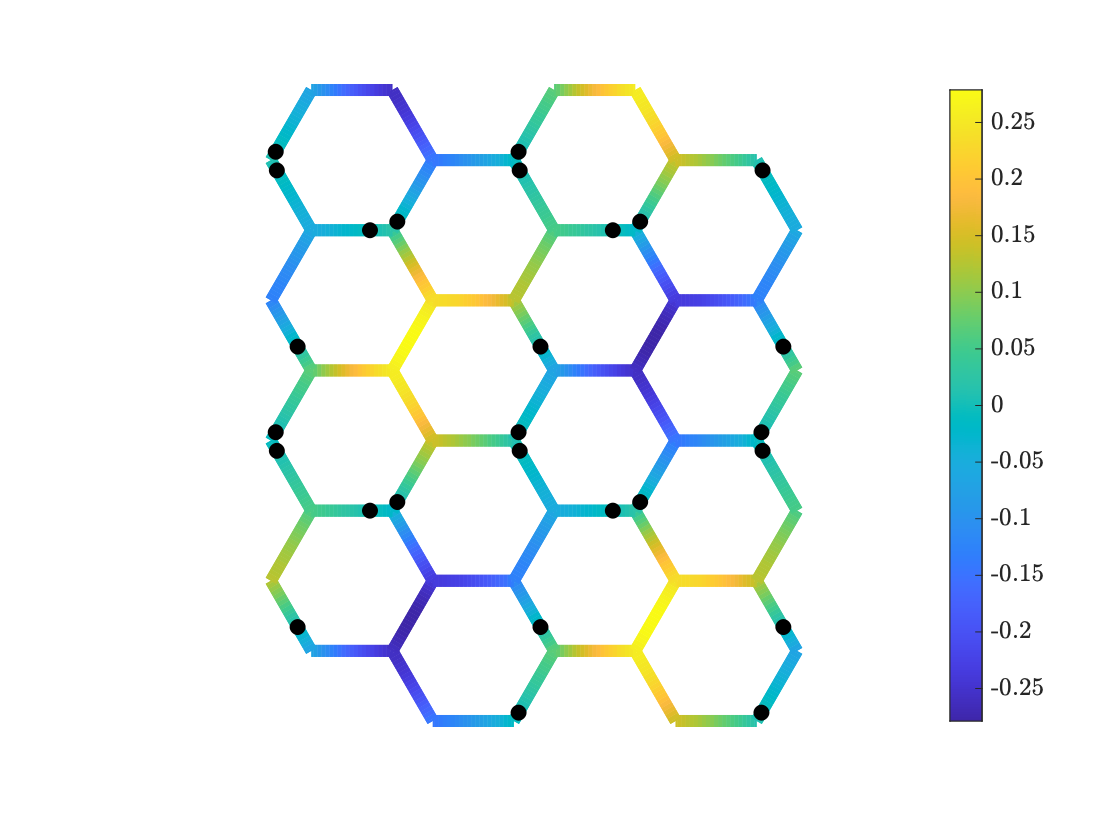

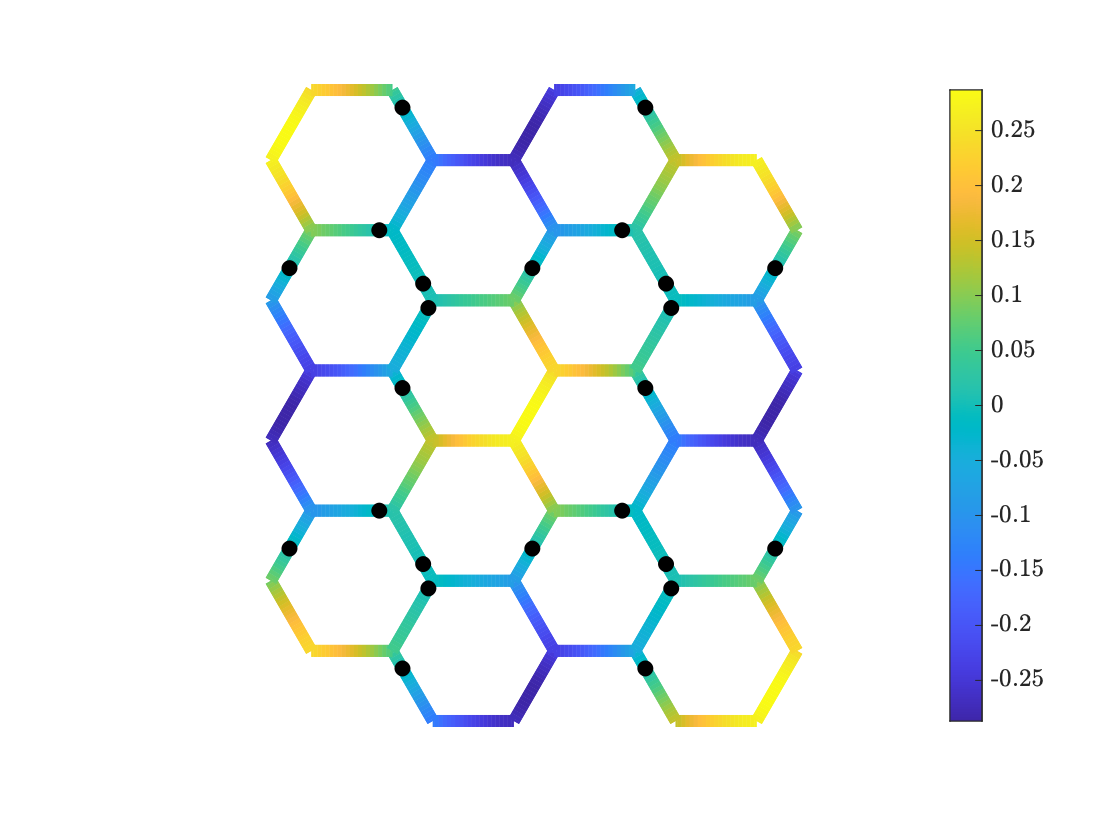

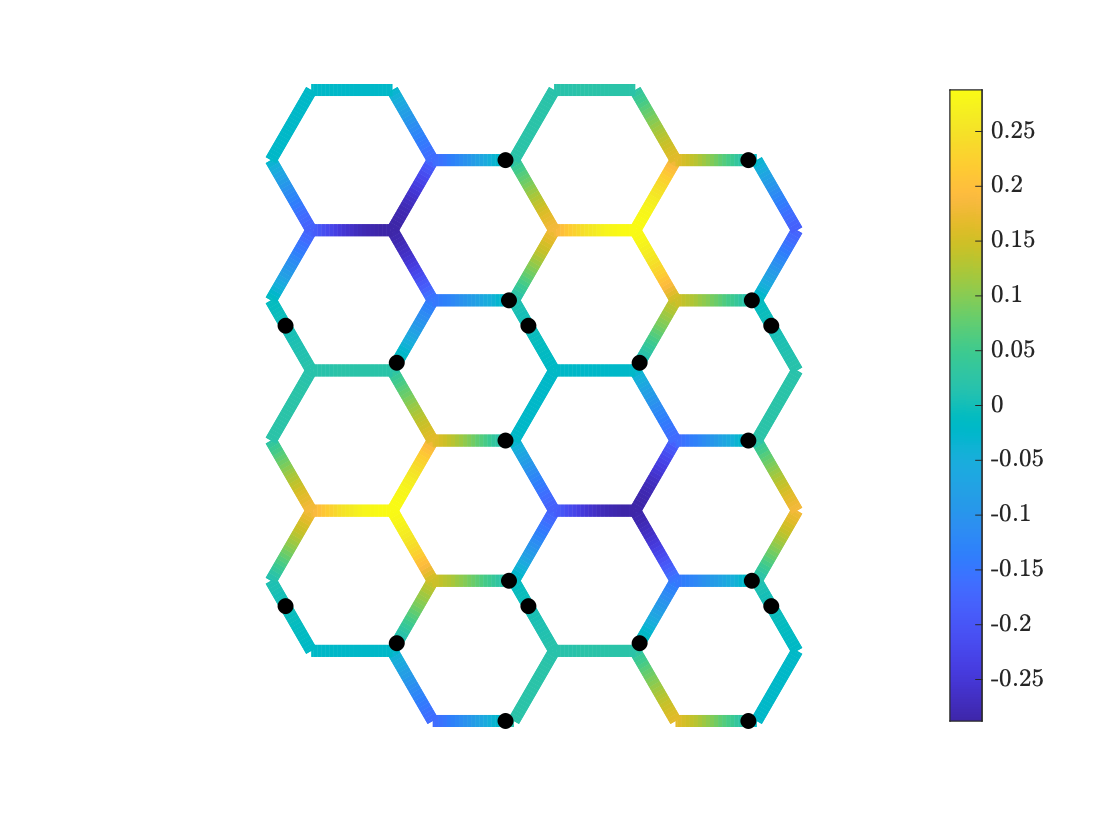

[V,~]=Phi.eigs(9);
U=Phi.gramSchmidt(V(:,6:9));
for k=1:4
    figure
    PhiX.pcolorPeriodicExtension(Phi,extensionMap,U(:,k))
end

### Delaunay Square 

This places random points along the edges of a square and in its interior, along with points at the four corners. It connects them into a Delaunay triangulation

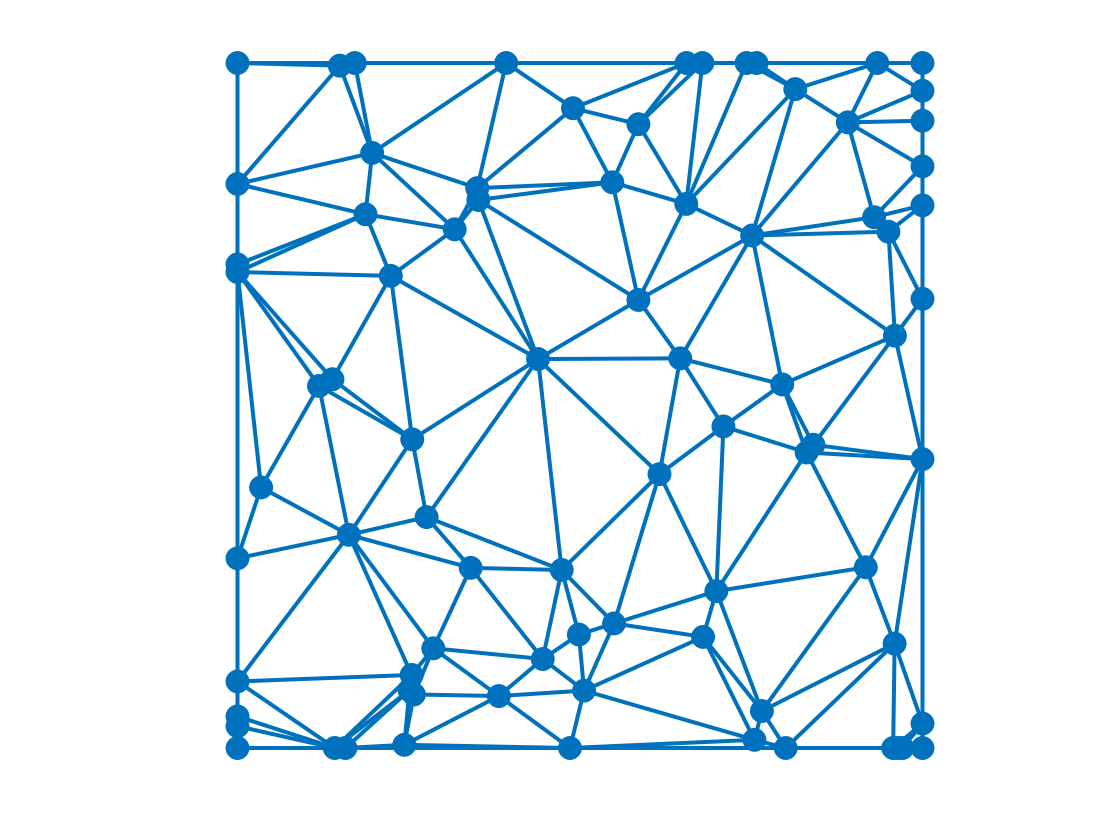

Phi=delaunaySquare('n',8);
Phi.plot('mutelayout')

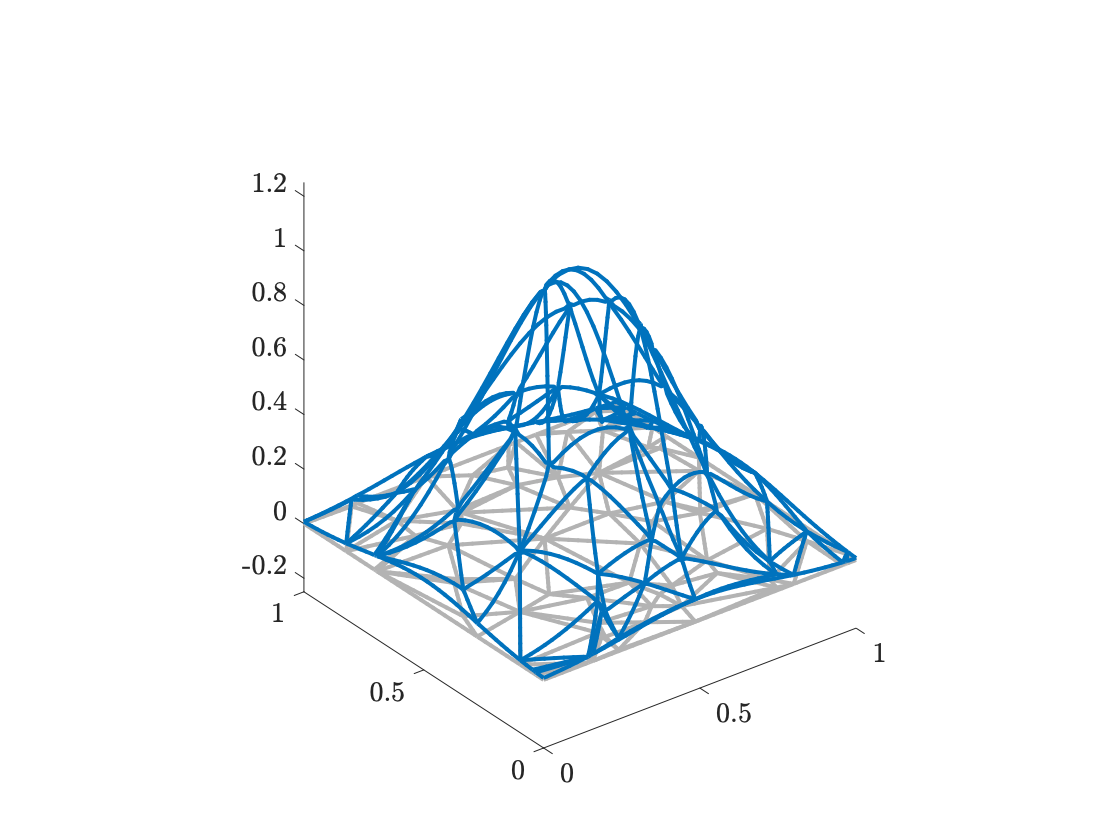

f=@(x1,x2) exp(-10*((x1-1/2).^2+(x2-1/2).^2));
Phi.applyGraphicalFunction(f);
Phi.plot

### Generate the QGLAB logo

The MATLAB logo is the ground state eigenfunction of an L-shaped domain (formed by removing one quarter of a square), subject to homogeneous Dirichlet boundary. We solve an equivalent problem on a quantum graph to define the QGLab logo. It need be rotated to form the logo.

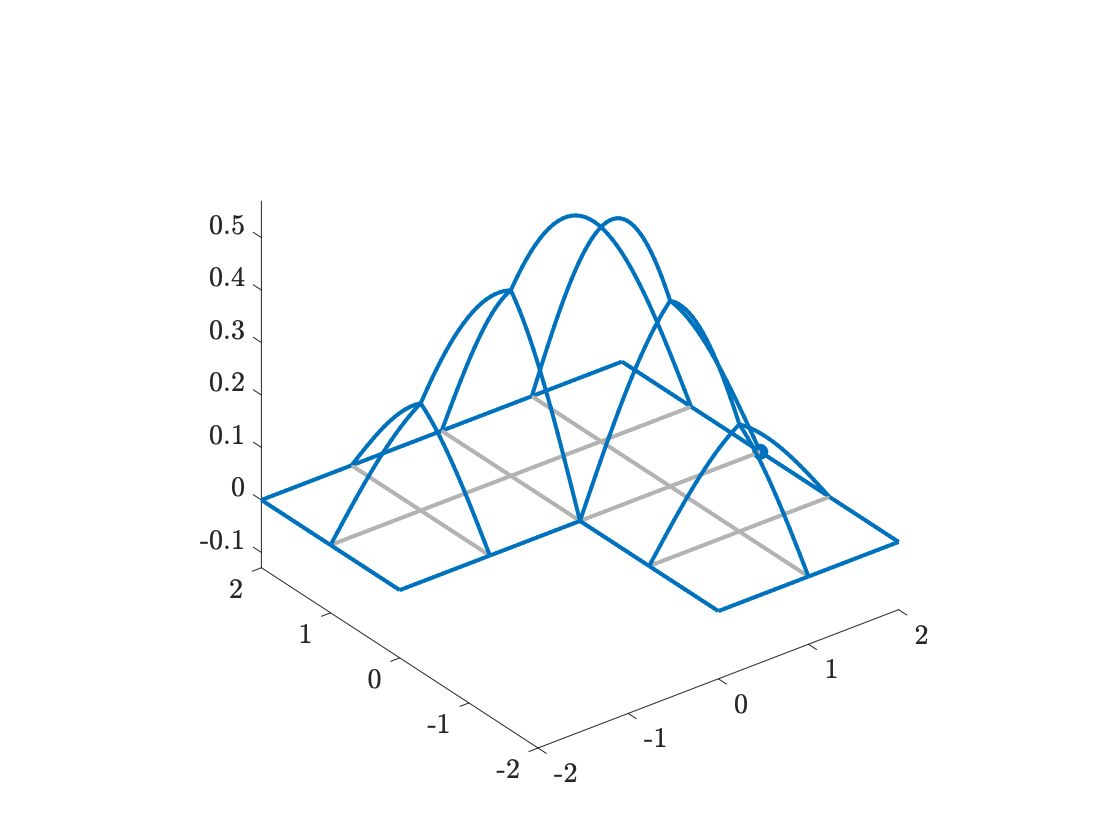

phi=matlabLogo('nx1',2);
[V,d]=phi.eigs(1);
phi.plot(V)

## Three dimensional templates 

The following graphs are given as the edges of the five platonic solids and some other geometric solids. They are all created using the solidT`emplates.m` function.

### Tetrahedron

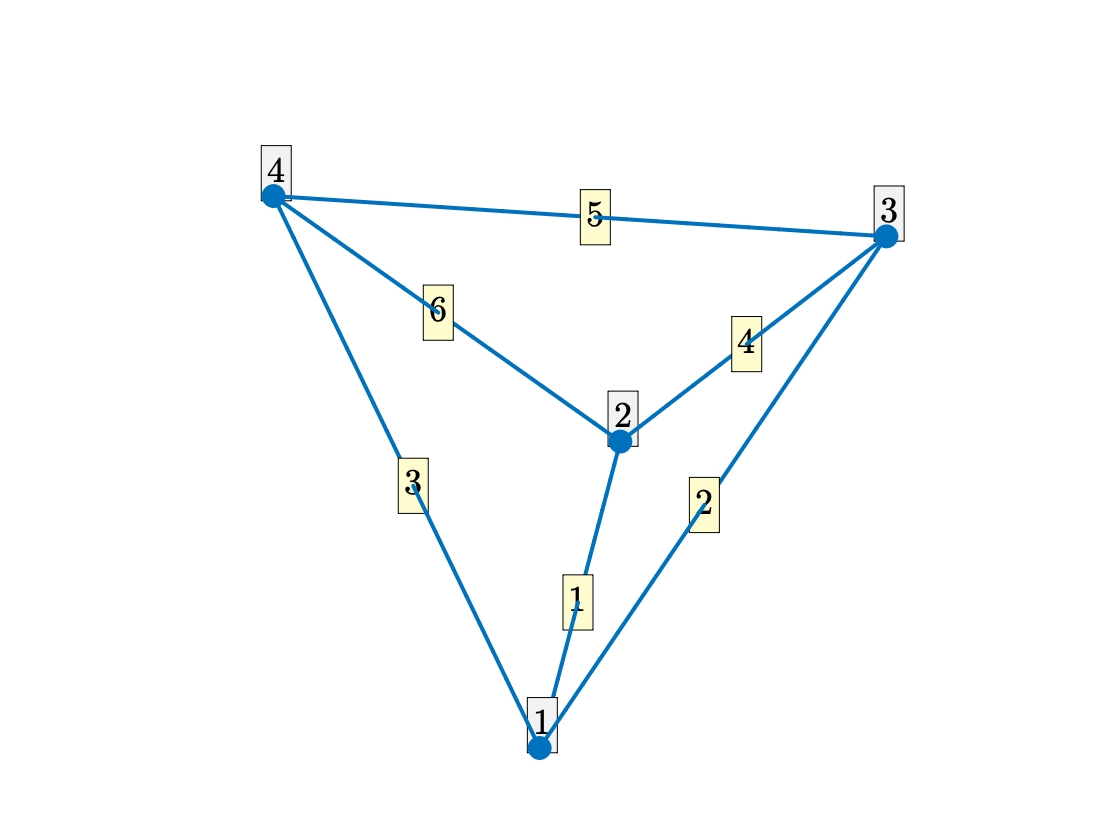

Phi=solidTemplates('tetrahedron');
Phi.plot('layout')

For these naturally three-dimensional graphs (which can be realized in $\mathbb{R}^2$ at the expense of ceasing to maintain their edge lengths, we provide the option of plotting in three dimensions, using color to indicate the $y$-value. Here we evaluate a Gaussian of random amplitutde along each edge of a tetrahedron and plot the result:

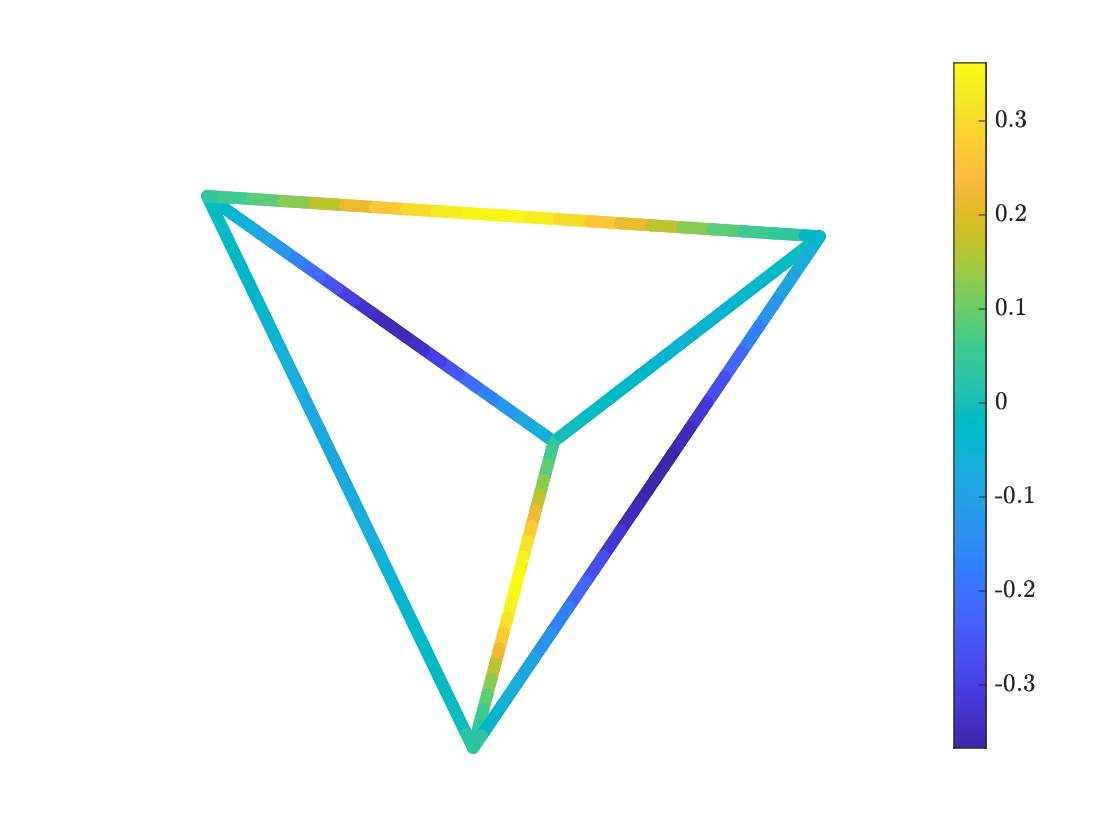

f=cell(1,6);
for k=1:6
    f{k}=@(x) (0.5-rand(1))*exp(-(10*(x-Phi.L(k)/2).^2));
end
Phi.applyFunctionsToAllEdges(f)
Phi.plot

f=Phi.secularDet;
disp(f)

$${\left(\cos\left(x\right)-1\right)}^{2}\,\left(\cos\left(x\right)+1\right)\,{\left(3\,\cos\left(x\right)+1\right)}^{3}$$

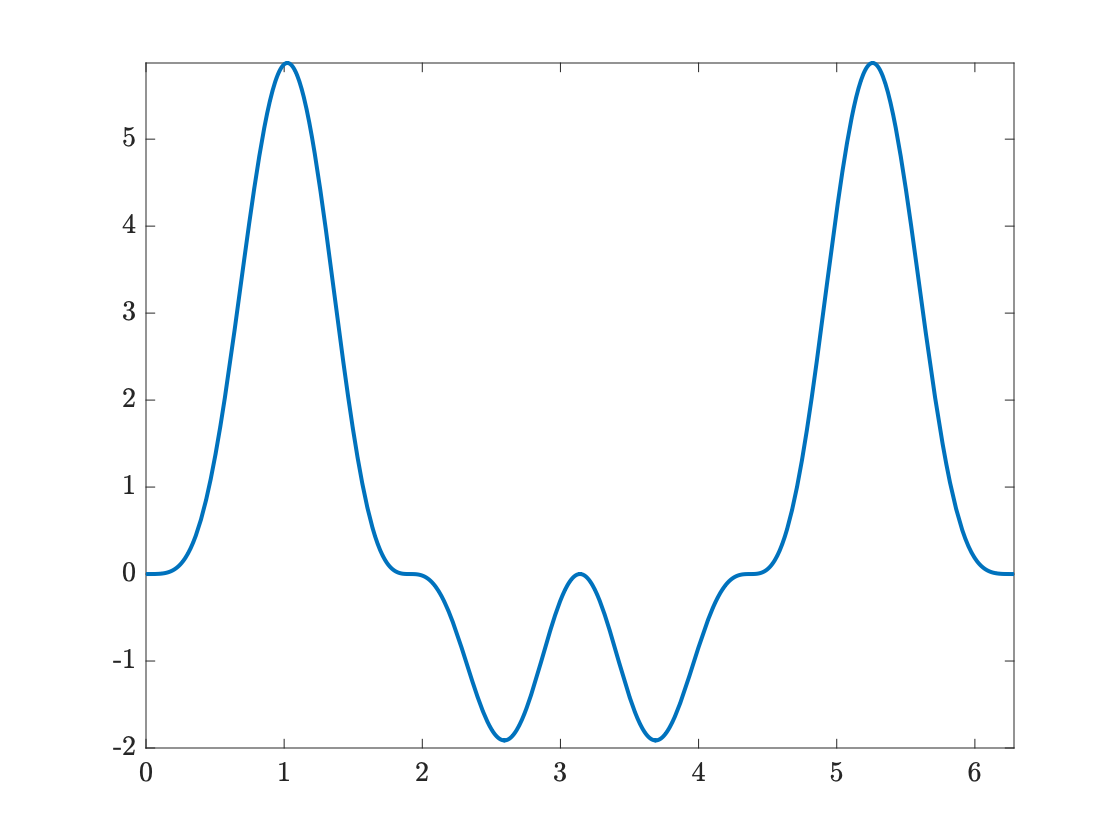

fplot(f,[0 2*pi])

### Cube

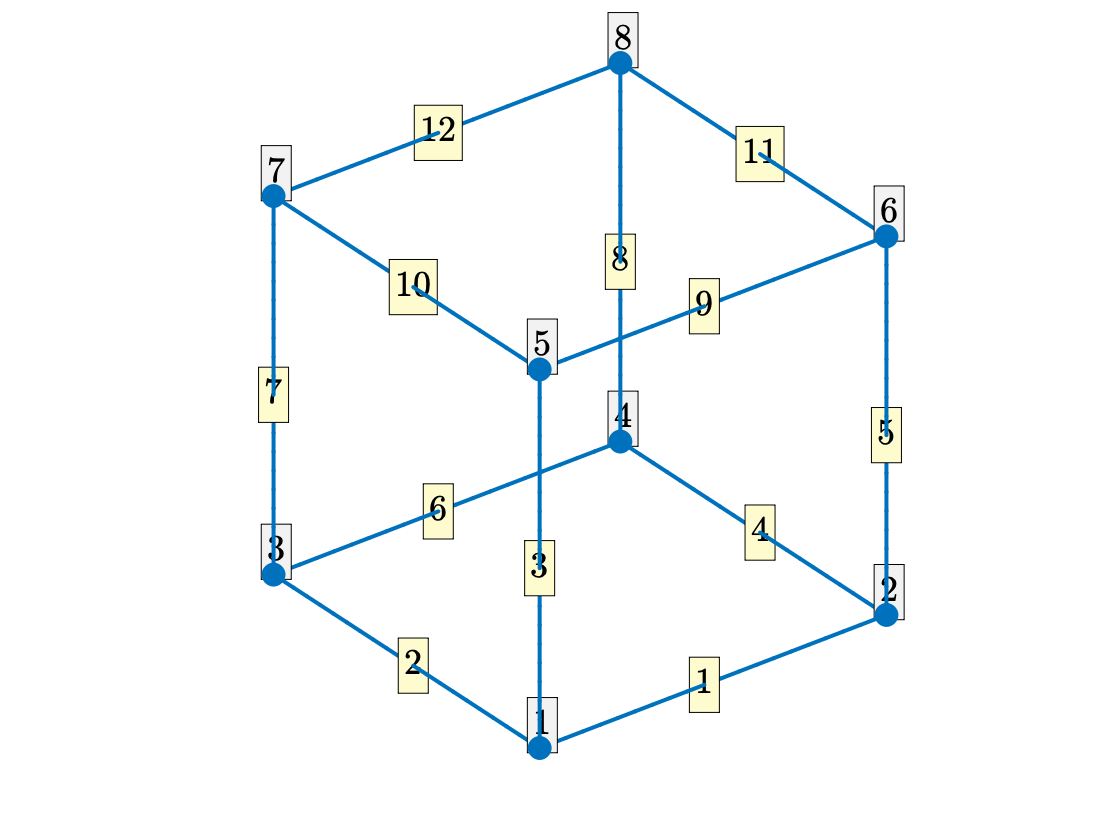

Phi=solidTemplates('cube');
Phi.plot('layout')

f=Phi.secularDet;
disp(f)

$$-\frac{{\sin\left(x\right)}^{6}\,{\left(9\,{\sin\left(x\right)}^{2}-8\right)}^{3}}{512}$$

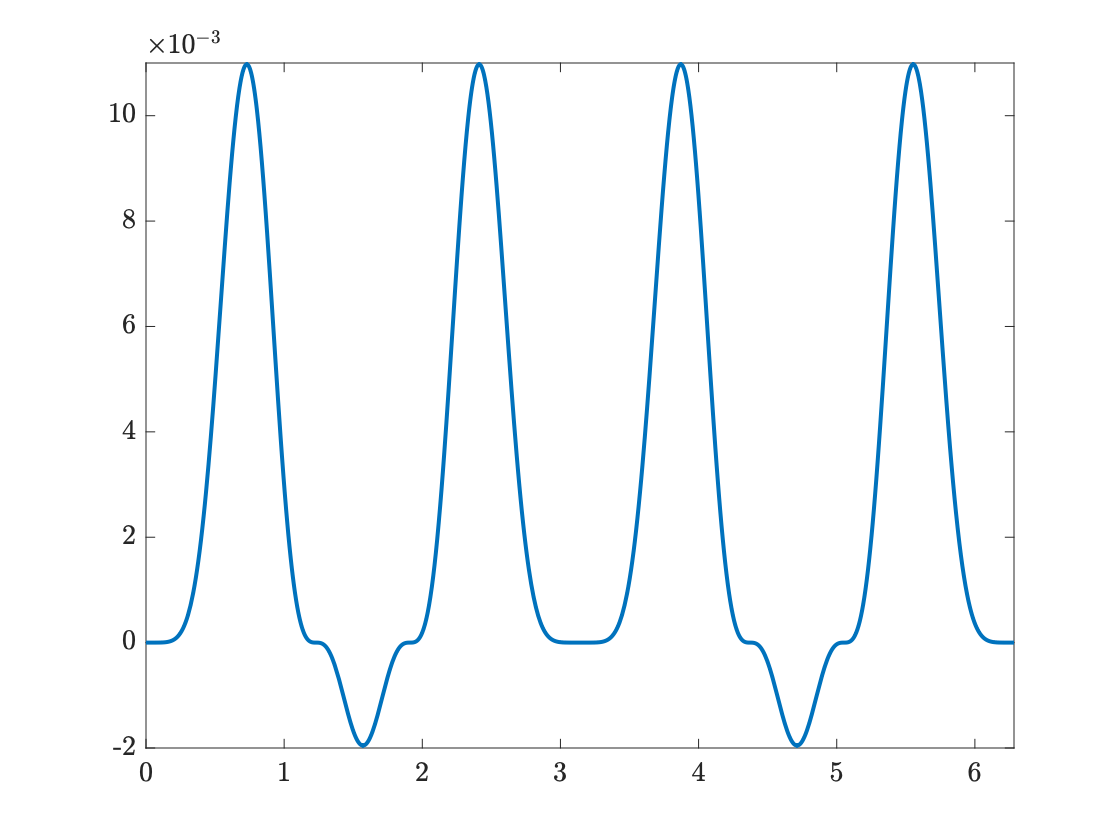

fplot(f,[0 2*pi])

### Octahedron

For the graphs below we plot the layout using the `mutelayout` option, since displaying the edge and node labels is just too busy.

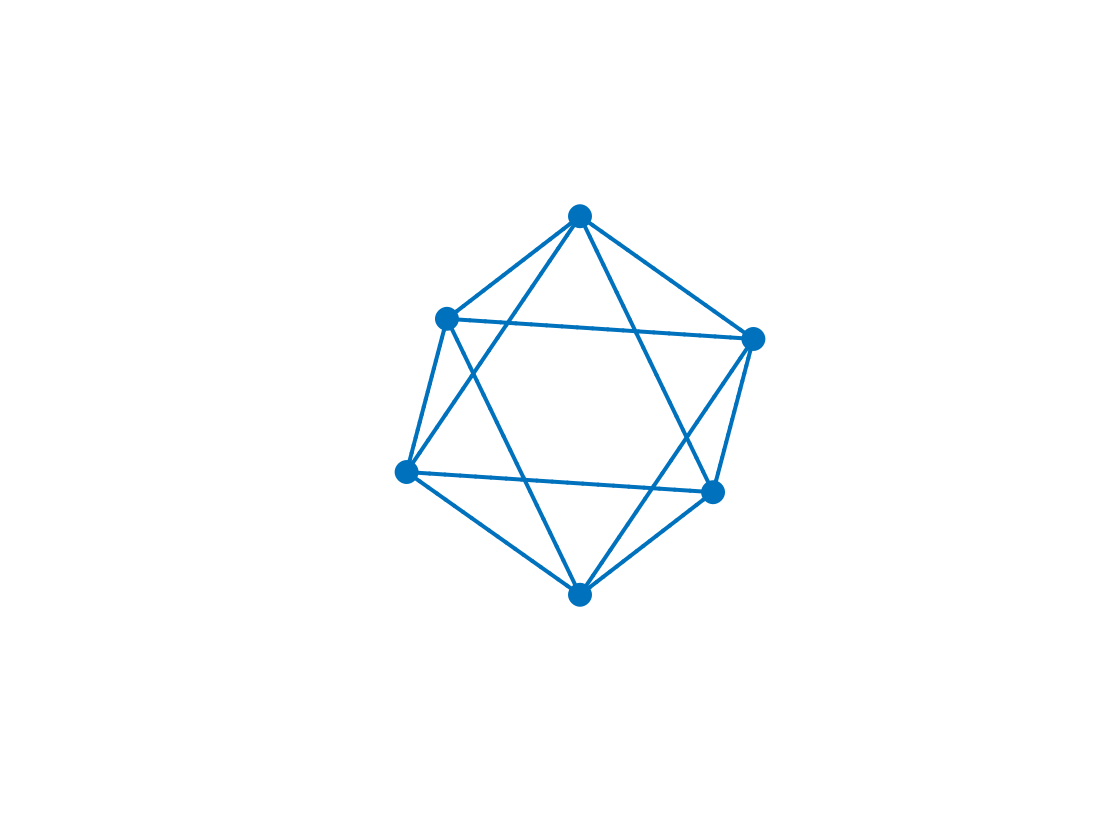

Phi=solidTemplates('octahedron');
Phi.plot('mutelayout')

f=Phi.secularDet;
disp(f)

$$\frac{{\sin\left(\frac{x}{2}\right)}^{8}\,{\left(4\,{\sin\left(\frac{x}{2}\right)}^{2}-3\right)}^{2}\,{\left(2\,{\sin\left(\frac{x}{2}\right)}^{4}-3\,{\sin\left(\frac{x}{2}\right)}^{2}+1\right)}^{3}}{9}$$

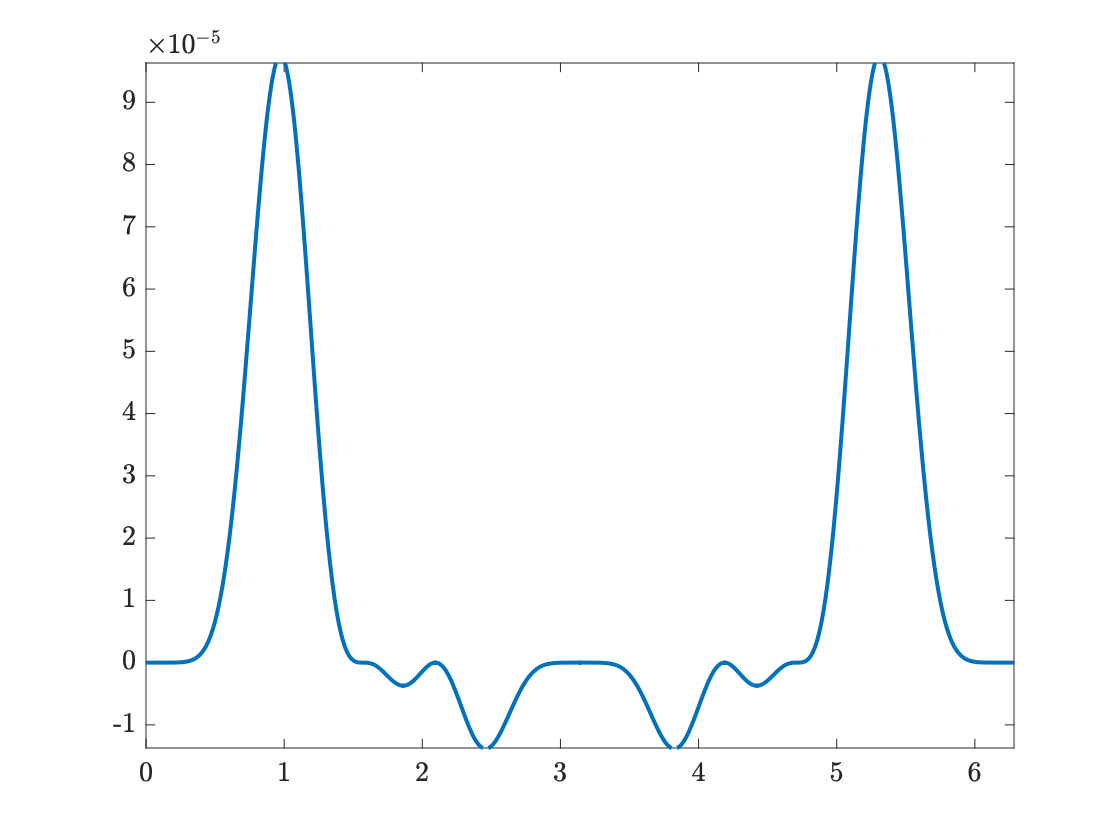

fplot(f,[0 2*pi])

Now we're going to plot some functions defined using `applyGraphicalFunction`. First, let's define a function $f(\mathbf{x})$ that decays rapidly away from a given point in space..

f = @(x1,x2,x3,x0)exp(-2*((x1-x0(1)).^2+(x2-x0(2)).^2+(x3-x0(3)).^2));
Nodes=[Phi.Nodes.x1 Phi.Nodes.x2 Phi.Nodes.x3];

#### Function with maximum at a vertex

Place the maximum at a vertex

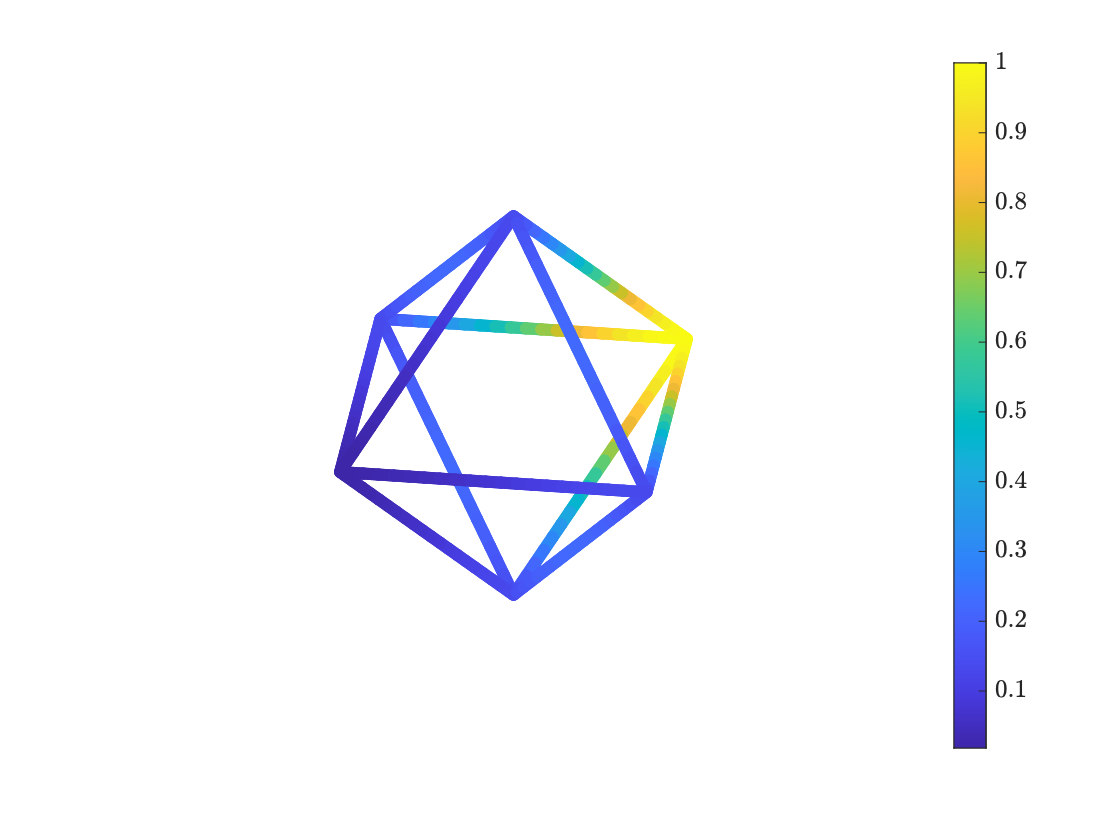

xV = Nodes(1,:);
fV =@(x1,x2,x3)f(x1,x2,x3,xV);
Phi.applyGraphicalFunction(fV)
Phi.plot

#### Function with maximum at the center of an edge

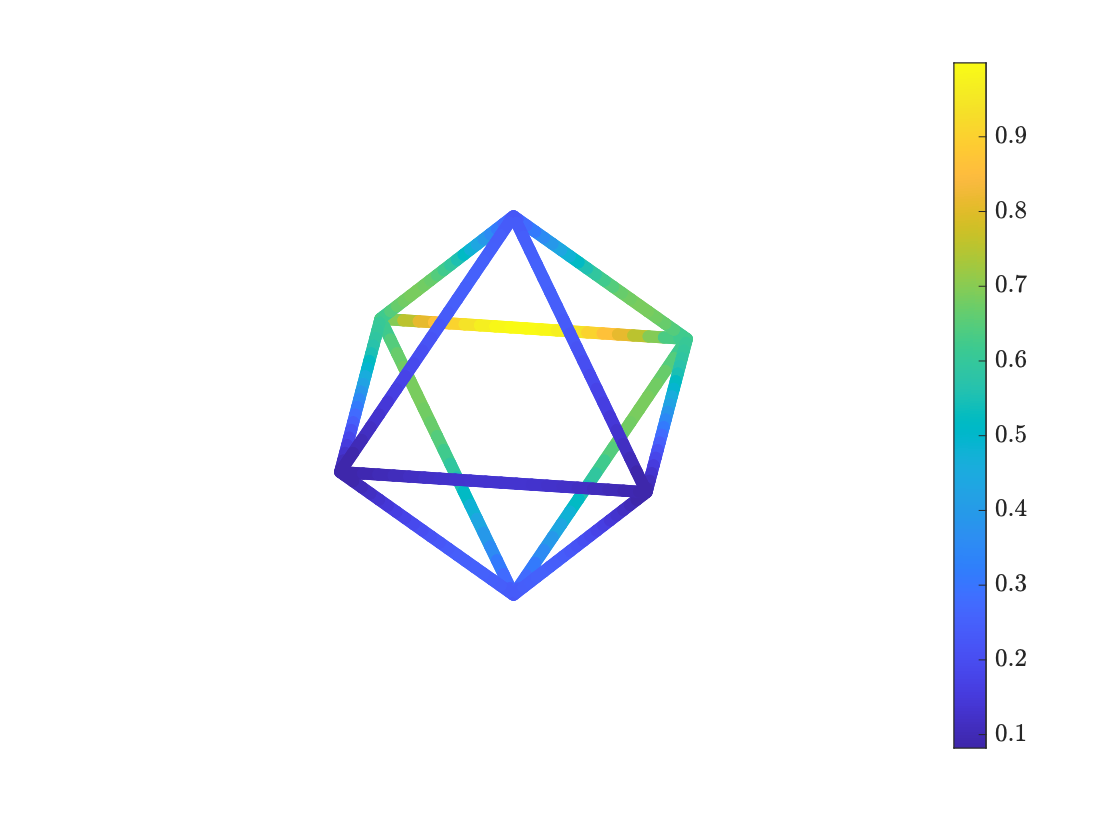

xE = (Nodes(1,:)+Nodes(2,:))/2; % Midpoint of an edge
fE =@(x1,x2,x3)f(x1,x2,x3,xE);
Phi.applyGraphicalFunction(fE)
Phi.plot

#### Function with a maximum at the center of a face

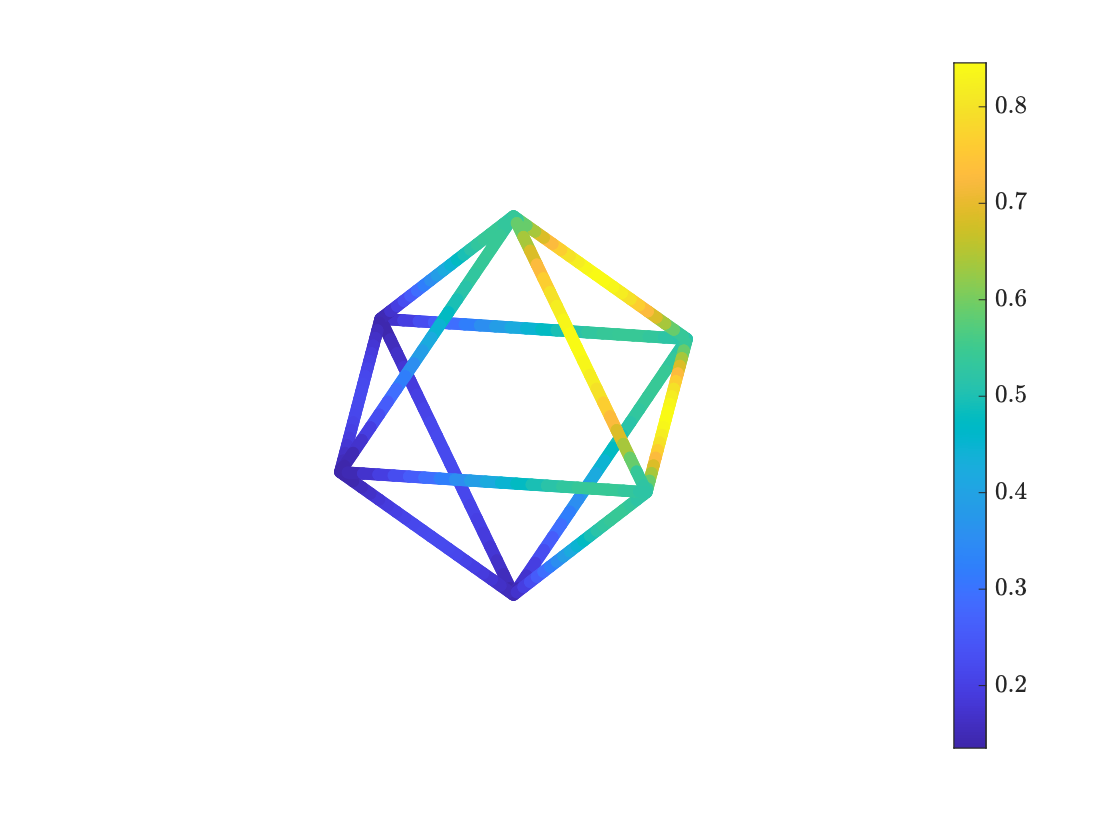

xF = (Nodes(1,:)+Nodes(4,:)+Nodes(5,:))/3; % Midpoint of a face
fF =@(x1,x2,x3)f(x1,x2,x3,xF);
Phi.applyGraphicalFunction(fF)
Phi.plot

### Dodecahedron

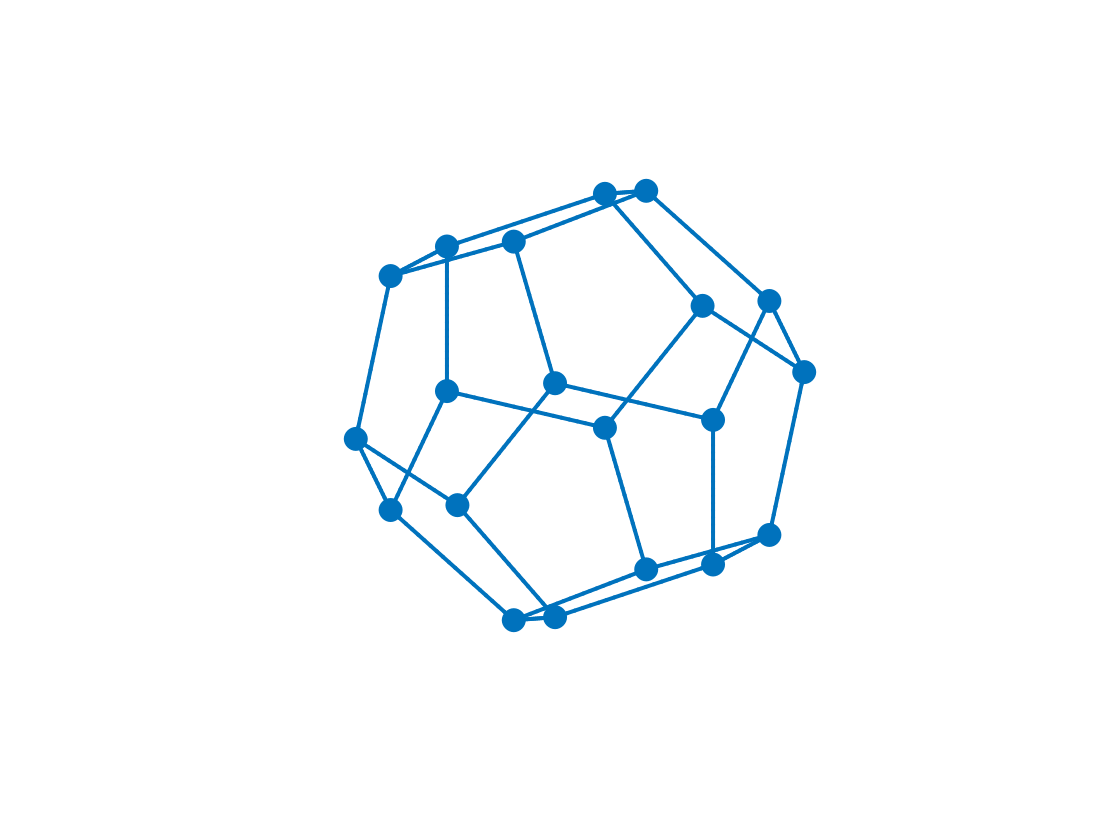

Phi=solidTemplates('dodecahedron');
Phi.plot('mutelayout')

f=Phi.secularDet;
disp(f)

$$-\frac{{\sin\left(\frac{x}{2}\right)}^{12}\,{\left(9\,\cos\left(2\,x\right)-1\right)}^{3}\,{\left(3\,{\sin\left(\frac{x}{2}\right)}^{4}-4\,{\sin\left(\frac{x}{2}\right)}^{2}+1\right)}^{5}\,{\left(12\,{\sin\left(\frac{x}{2}\right)}^{4}-16\,{\sin\left(\frac{x}{2}\right)}^{2}+5\right)}^{4}}{625}$$

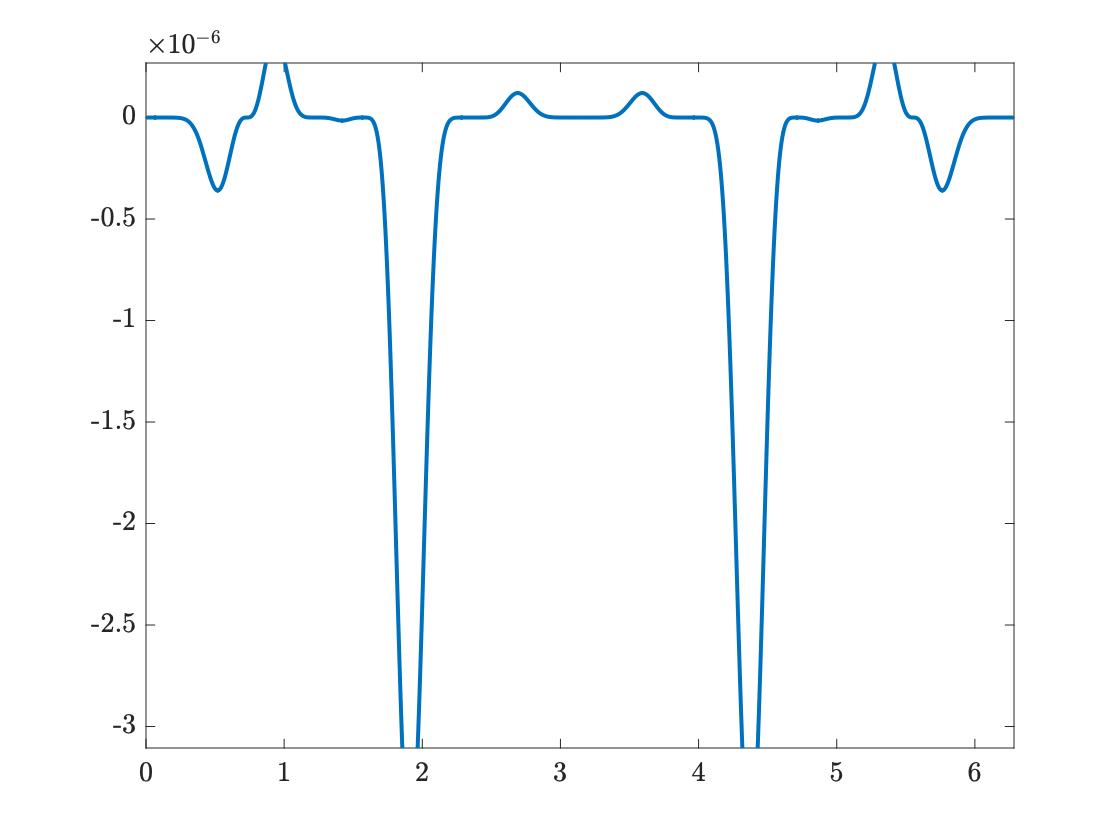

fplot(f,[0 2*pi]); 

### Icosahedron

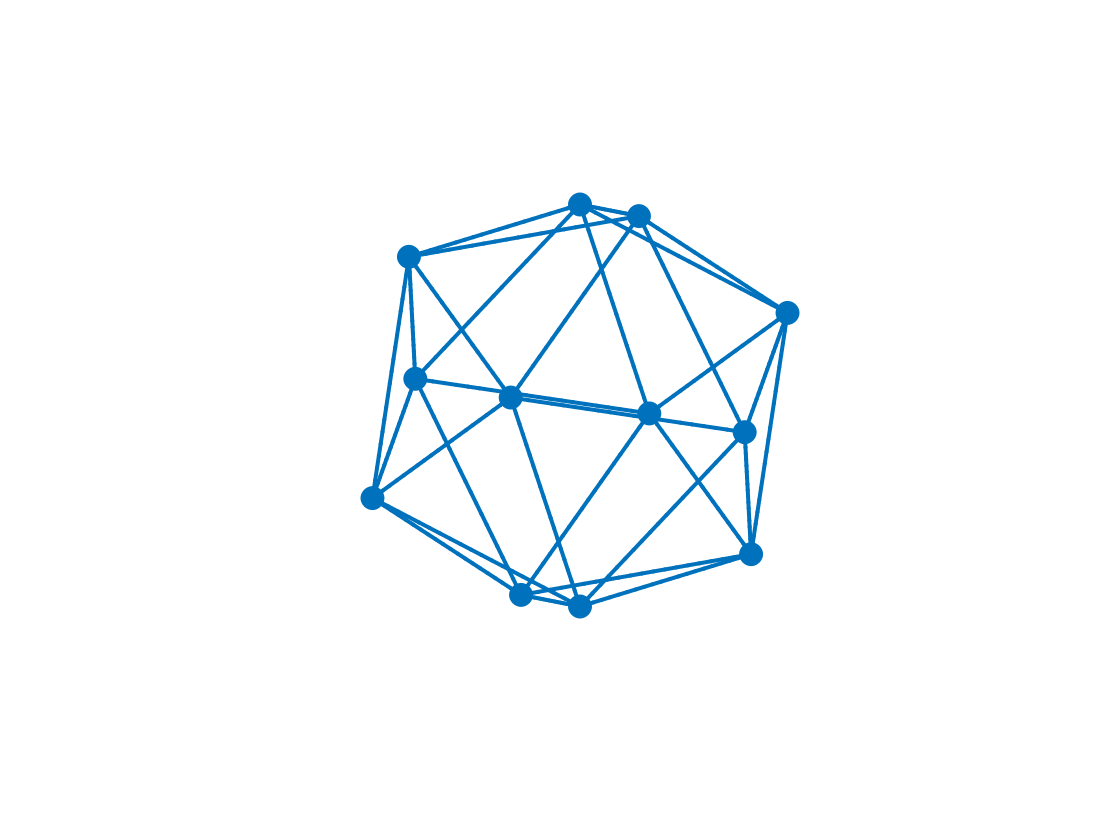

Phi=solidTemplates('icosahedron');
Phi.plot('mutelayout')

f=Phi.secularDet;
disp(f)

$$-{\left(\cos\left(x\right)-1\right)}^{10}\,{\left(\cos\left(x\right)+1\right)}^{9}\,{\left(5\,\cos\left(x\right)+1\right)}^{5}\,{\left(5\,{\cos\left(x\right)}^{2}-1\right)}^{3}$$

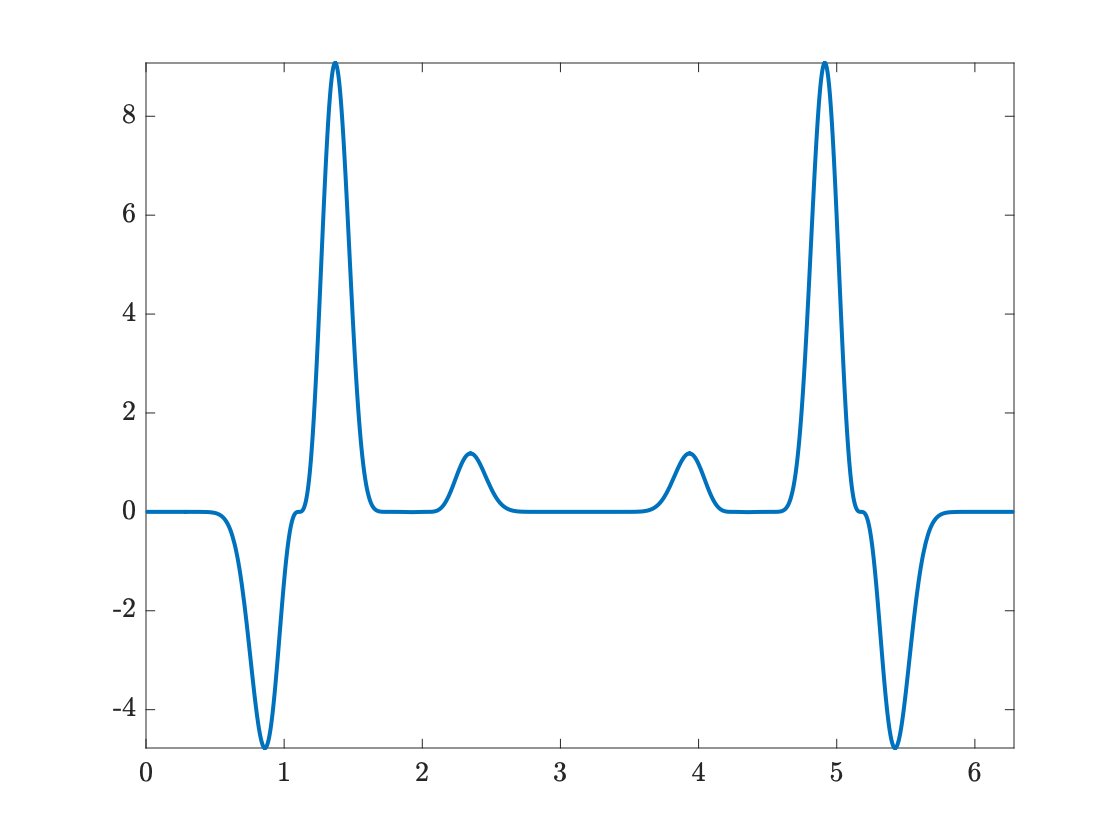

fplot(f,[0 2*pi])

### Cuboctahedron

Not a Platonic solid, but fun!

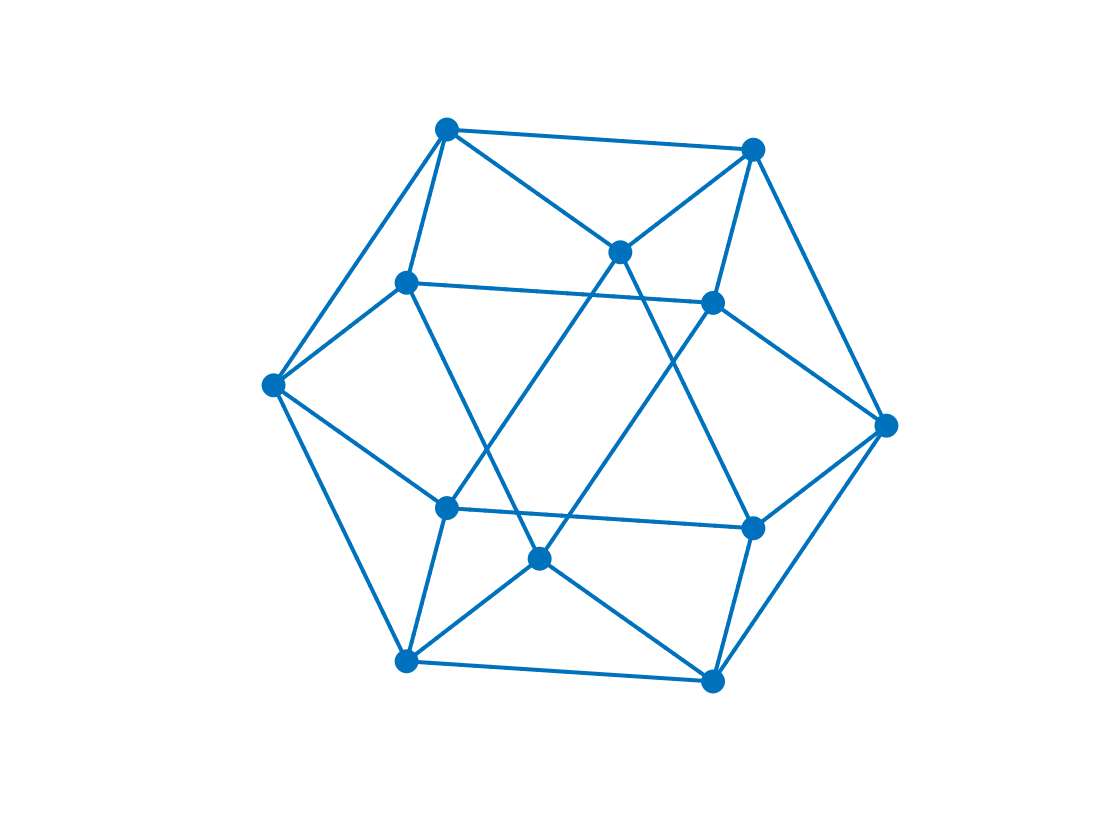

Phi=solidTemplates('cuboctahedron');
Phi.plot('mutelayout')

f=Phi.secularDet;
disp(f)

$${\cos\left(x\right)}^{3}\,{\left(\cos\left(x\right)-1\right)}^{7}\,{\left(\cos\left(x\right)+1\right)}^{6}\,{\left(2\,\cos\left(x\right)-1\right)}^{3}\,{\left(2\,\cos\left(x\right)+1\right)}^{5}$$

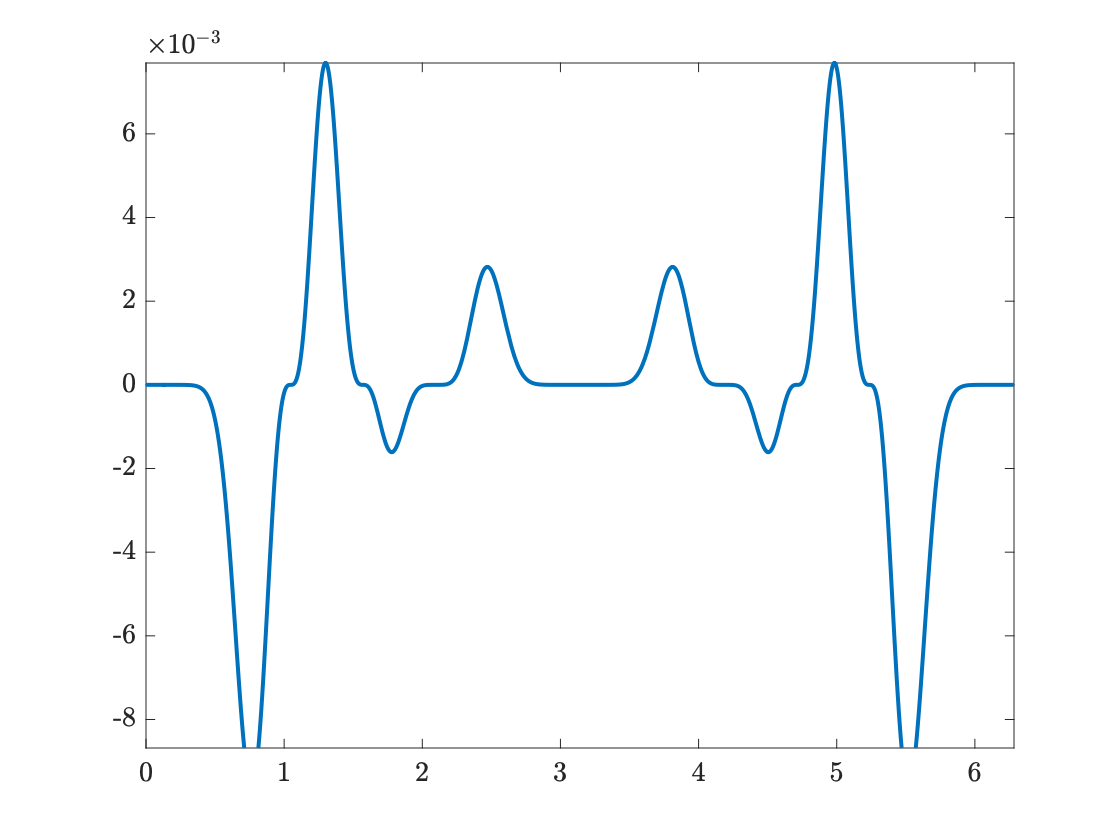

fplot(f,[0 2*pi])

### Buckyball

This monster has 60 vertices and 90 edges. My brand new MacBook Pro choked when it tried to compute the secular determinant. Maybe yours is powerful enough. I had to comment out the secular determinant.

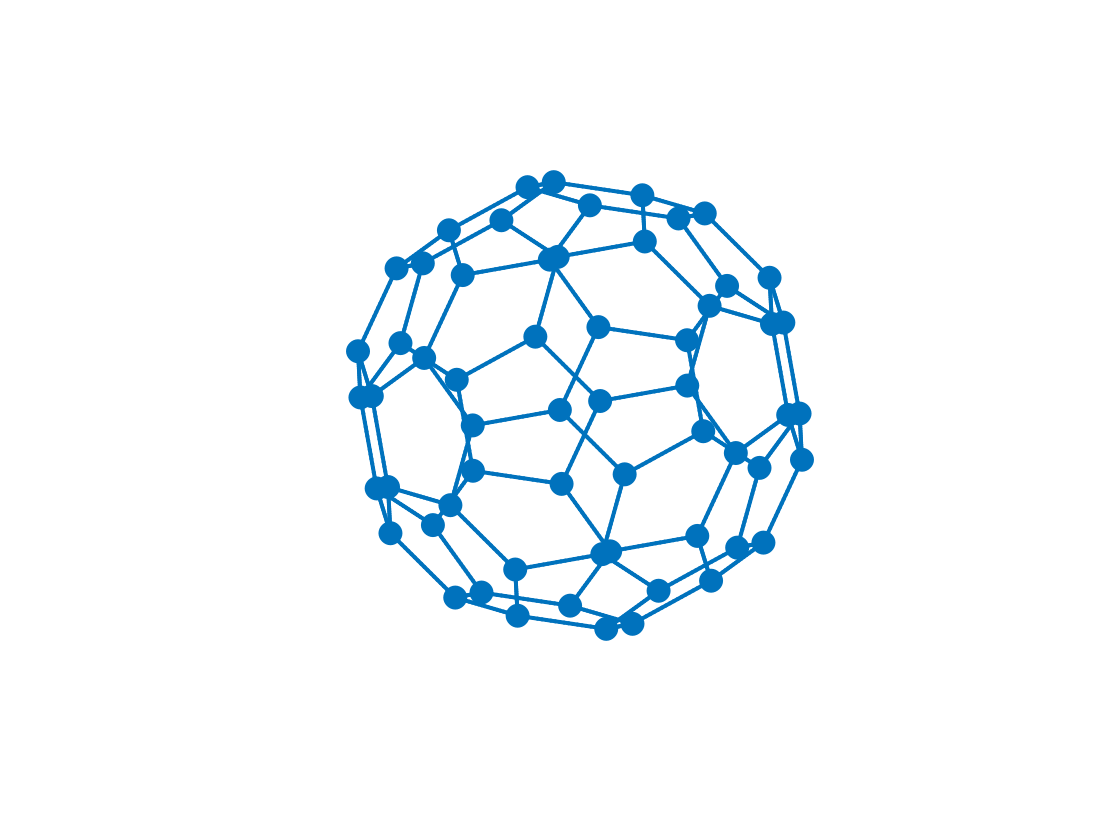

Phi=solidTemplates('buckyball');
Phi.plot('mutelayout')

Uncomment the following to see if your computer is powerful enough to compute this secular determinant.

% Phi.secularDet;
% disp(f);
% fplot(f,[0 2*pi])